# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all
close all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"

plotnam = "2-Schlogl"

plotnam = "2-Schlogl"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov"

plotnam = "Selkov model"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cc} 1 & 1\\ 2 & 2\\ 2.1654 & 1.0930\\ 1.0930 & 2.1654\\ 2.8367 & 1.1633\\ 1.1633 & 2.8367\\ 3 & 3\\ 2.9070 & 1.8346\\ 1.8346 & 2.9070 \end{array}\right)$$

hc_net

hc_net =      3     5     1
     4     6     1
     8     7     5
     9     7     6


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;

#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')

#### Sample space uniform and plot

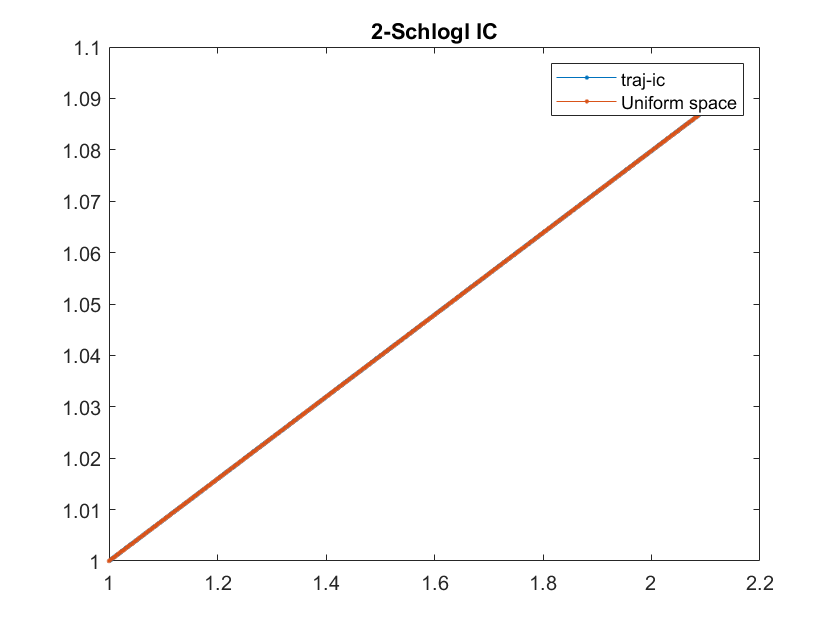

%Space uniform sampling
traj_pts = 500;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);
%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

#### Load from existing data

save('traj_n_s_2000_Schlogl.mat',"traj_n_s")

load('traj_n_s_2000_Schlogl.mat')
traj = traj_n_s; traj_pts = size(traj,1);
[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);

load("..\Data\Schlogl_1_2_descend_1_2straight_500_10-Jul-2022.mat")
iter

iter = 100

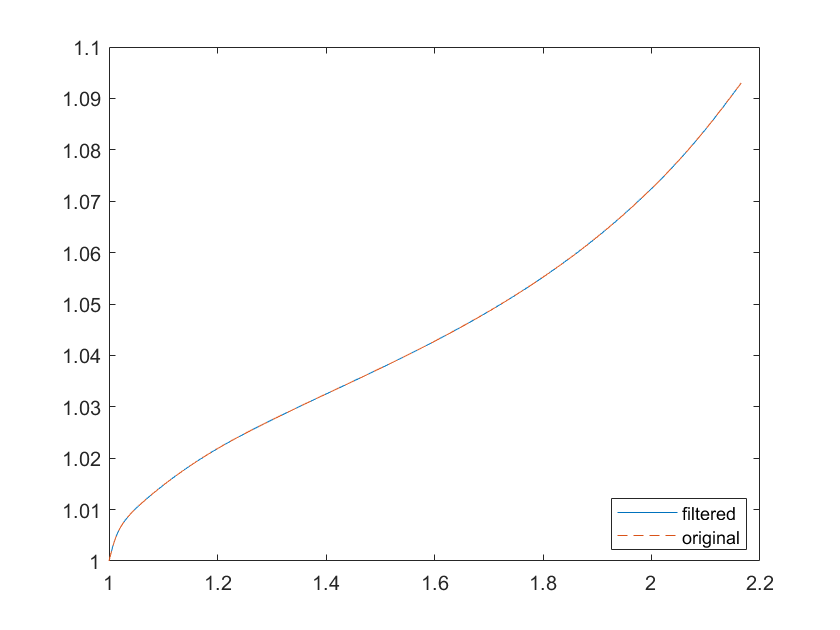

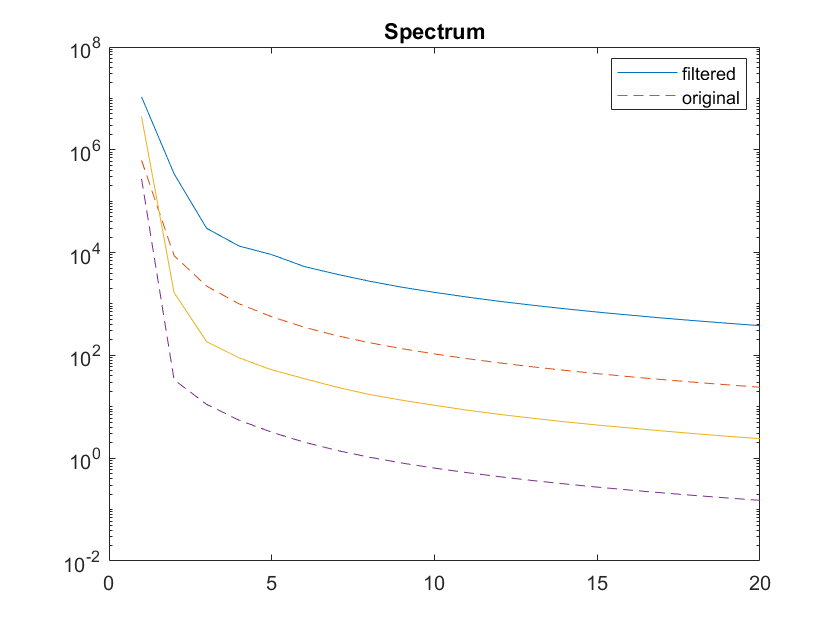

iter = 45;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
traj = time_uniform_filter(PS_traj(:,1:num_spec),t_traj,2000,40);

[traj,len_curve_prime] = space_uniform_sampling(traj,2000);

[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
%delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,20);
delta_x_s =  smooth_traj_butter(delta_x,5); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1);

%Initialize arrays for saving and delta_x_s
Initialize_descender

S_arr =    0.016810810232826



%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'straight_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_500_11-Jul-2022.mat"

%Save data to file in the data folder (for spiral)
%savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
%+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

%Save plots 
save_plot_name_root = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_'+string(traj_pts)+'_'+string(date)

save_plot_name_root = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022"


%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_PS_traj_IC.png"

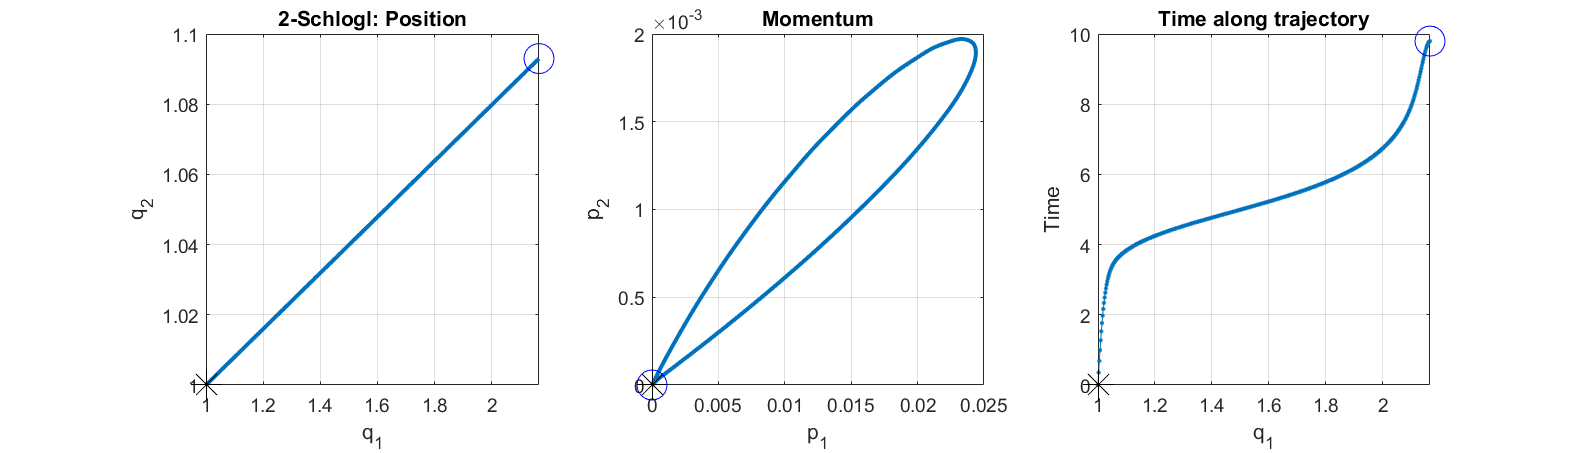

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);


%delta_x_s
delta_x_s =  smooth_traj_butter(delta_x,f0); 

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax_IC.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax_IC.png"

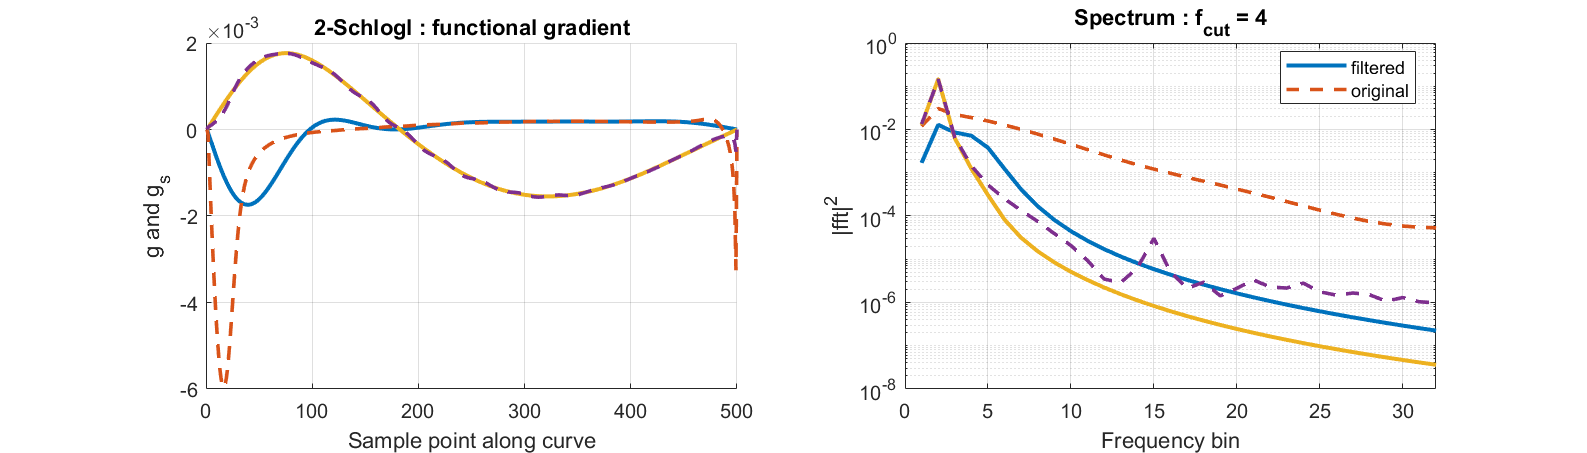

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);

## Perform the actual descent

%Actual descender
eps_ic = 1; eps = eps_ic; eps_min = 0.01;     %Initial and least step size
delta_S = 10; err_thresh = 10^(-1); 
f0_max = 40; f0_step = 0.1; f0_init = f0;
eps_S_thresh = 10^(-7); delta_S_thresh = 10^(-7);
iter_max = 120; iter = 1; a_min = 0.01;

iter_max = 120;  a_min = 0.001;


delta_S =      4.192880460884840e-08


ans =   41.000000000000000   1.000000000000000   0.016808430163384   0.000000041928805   4.299999999999999


delta_S =     -1.092708942120046e-05


ans =   42.000000000000000   1.000000000000000   0.016797503073963  -0.000010927089421   4.399999999999999


delta_S =      6.839616364343049e-06


ans =   43.000000000000000   1.000000000000000   0.016804342690327   0.000006839616364   4.399999999999999


delta_S =      9.790376791427025e-07


ans =   44.000000000000000   1.000000000000000   0.016805321728006   0.000000979037679   4.399999999999999


delta_S =      5.847009398492198e-07


ans =   45.000000000000000   1.000000000000000   0.016805906428946   0.000000584700940   4.399999999999999


delta_S =      6.287567562573981e-07


ans =   46.000000000000000   1.000000000000000   0.016806535185702   0.000000628756756   4.399999999999999


delta_S =      4.434635625244487e-07


ans =   47.000000000000000   1.000000000000000   0.016806978649265   0.000000443463563   4.399999999999999


delta_S =      6.418227884406880e-07


ans =   48.000000000000000   1.000000000000000   0.016807620472053   0.000000641822788   4.399999999999999


delta_S =      4.488926090701062e-07


ans =   49.000000000000000   1.000000000000000   0.016808069364662   0.000000448892609   4.399999999999999


delta_S =      2.169873020846369e-08


ans =   50.000000000000000   1.000000000000000   0.016808091063392   0.000000021698730   4.399999999999999


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_50.png"

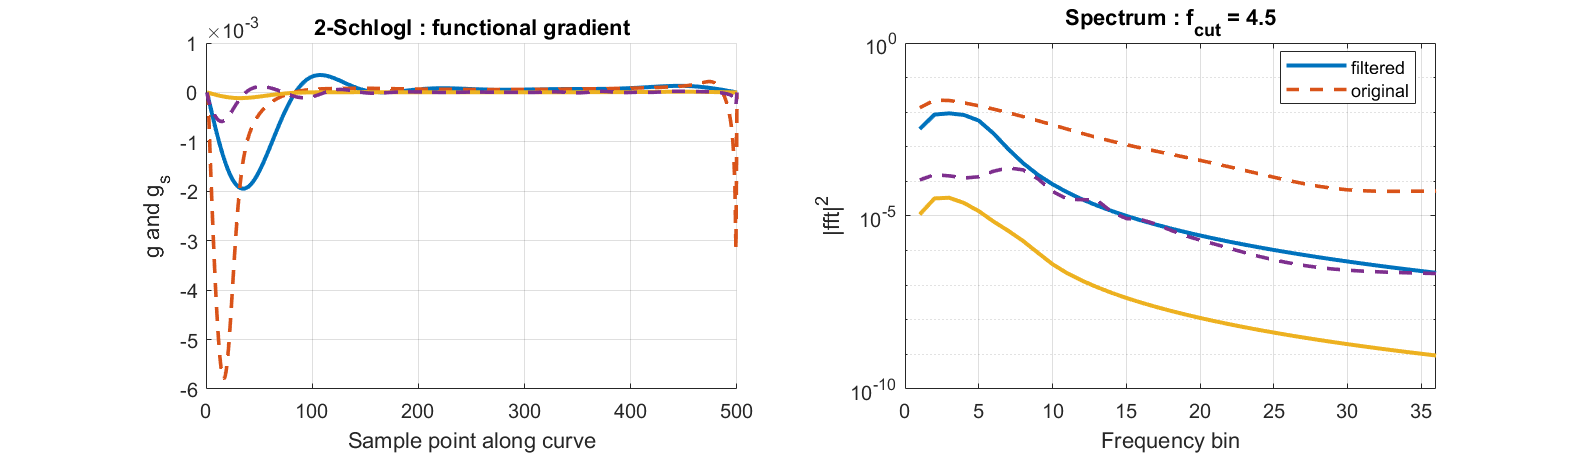

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_50.png"

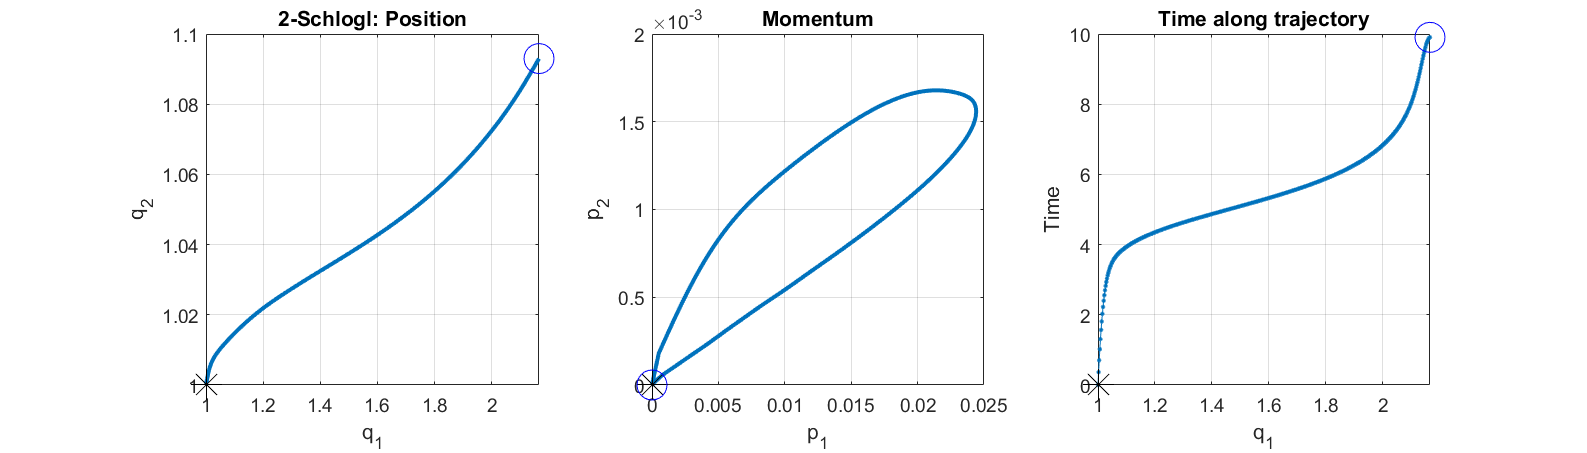

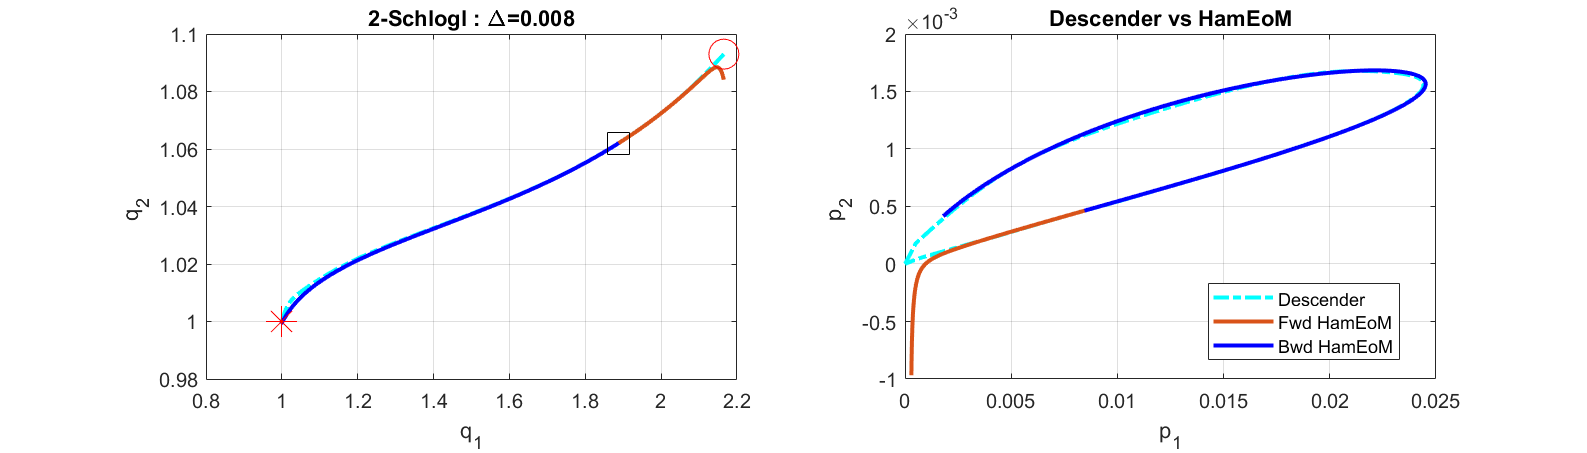

a =    0.008407029451883


delta_S =     -1.032371209121544e-05


ans =   51.000000000000000   1.000000000000000   0.016797767351301  -0.000010323712091   4.499999999999998


delta_S =      7.196533668669264e-06


ans =   52.000000000000000   1.000000000000000   0.016804963884970   0.000007196533669   4.499999999999998


delta_S =      6.140705316737272e-07


ans =   53.000000000000000   1.000000000000000   0.016805577955502   0.000000614070532   4.499999999999998


delta_S =      6.139832185274308e-07


ans =   54.000000000000000   1.000000000000000   0.016806191938720   0.000000613983219   4.499999999999998


delta_S =      6.176431027460350e-07


ans =   55.000000000000000   1.000000000000000   0.016806809581823   0.000000617643103   4.499999999999998


delta_S =      4.385485212442253e-07


ans =   56.000000000000000   1.000000000000000   0.016807248130344   0.000000438548521   4.499999999999998


delta_S =      6.297254665221796e-07


ans =   57.000000000000000   1.000000000000000   0.016807877855811   0.000000629725467   4.499999999999998


delta_S =      4.229608309043453e-07


ans =   58.000000000000000   1.000000000000000   0.016808300816641   0.000000422960831   4.499999999999998


delta_S =      2.023670581906278e-07


ans =   59.000000000000000   1.000000000000000   0.016808503183700   0.000000202367058   4.499999999999998


delta_S =      2.124757567043001e-07


ans =   60.000000000000000   1.000000000000000   0.016808715659456   0.000000212475757   4.499999999999998


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_60.png"

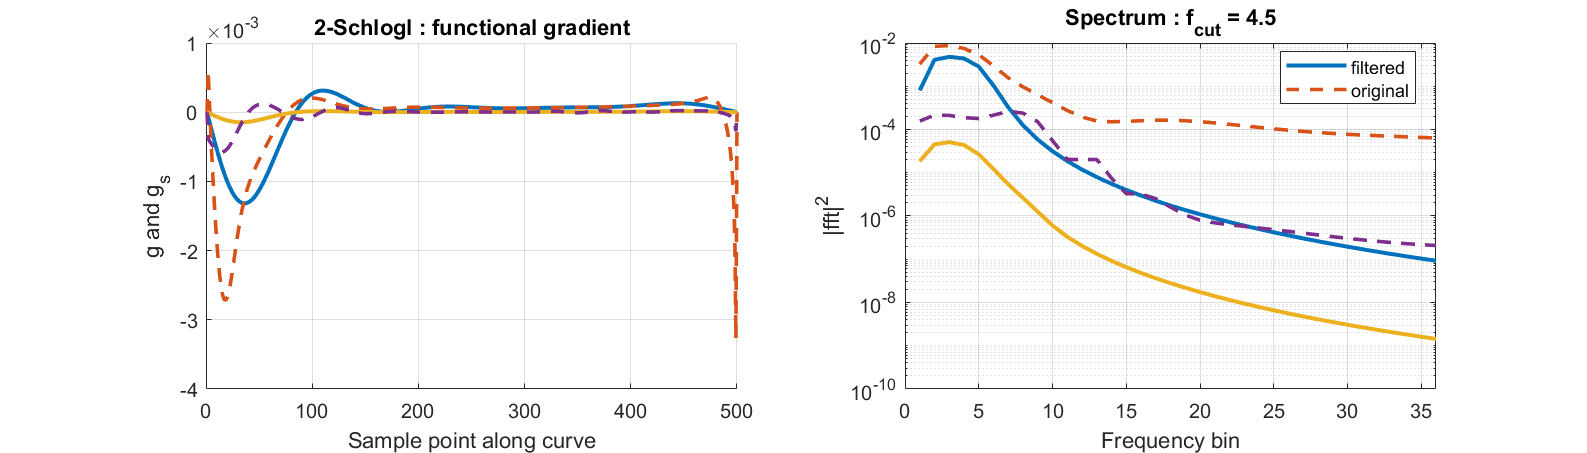

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_60.png"

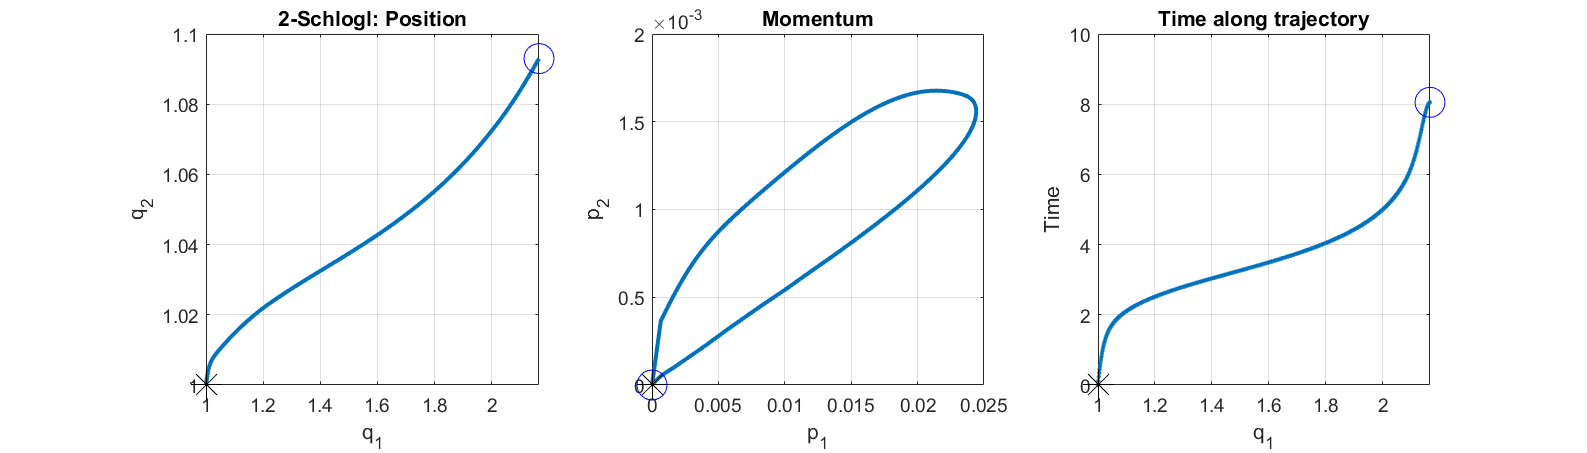

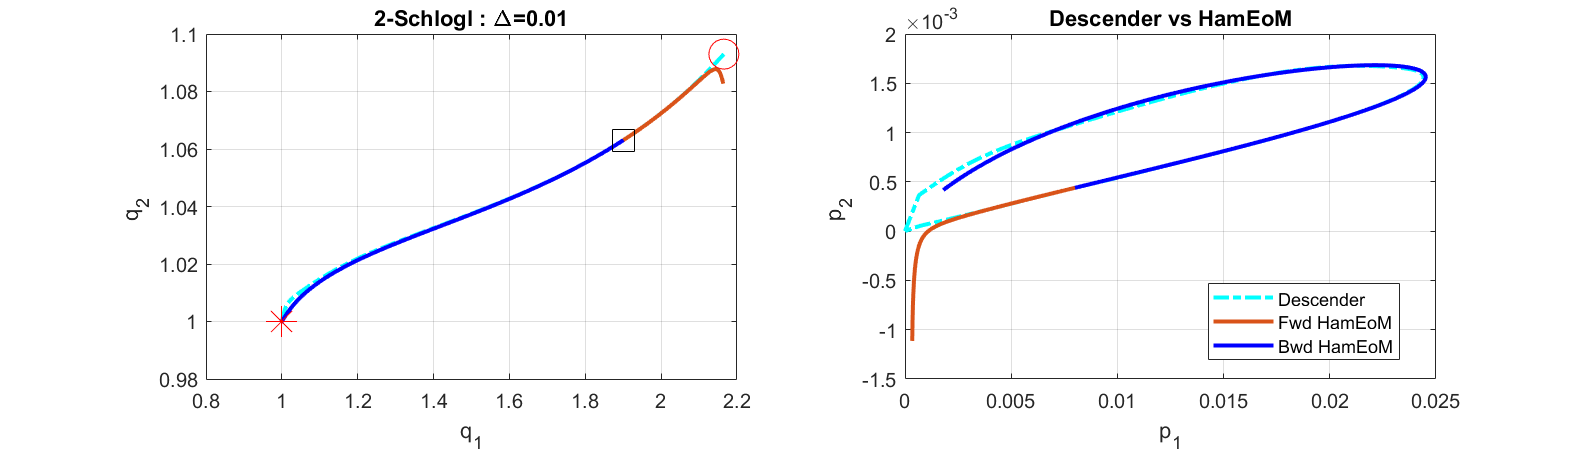

a =    0.009885633230814


delta_S =      3.748537755095260e-07


ans =   61.000000000000000   1.000000000000000   0.016809090513232   0.000000374853776   4.499999999999998


delta_S =     -1.191710672782120e-07


ans =   62.000000000000000   1.000000000000000   0.016808971342165  -0.000000119171067   4.499999999999998


delta_S =      1.877479041921537e-07


ans =   63.000000000000000   1.000000000000000   0.016809159090069   0.000000187747904   4.499999999999998


delta_S =     -8.046169791206537e-08


ans =   64.000000000000000   1.000000000000000   0.016809078628371  -0.000000080461698   4.499999999999998


delta_S =     -1.054731519781540e-05


ans =   65.000000000000000   1.000000000000000   0.016798531313173  -0.000010547315198   4.599999999999998


delta_S =      6.701801651704670e-06


ans =   66.000000000000000   1.000000000000000   0.016805233114825   0.000006701801652   4.599999999999998


delta_S =      5.391622456066281e-07


ans =   67.000000000000000   1.000000000000000   0.016805772277070   0.000000539162246   4.599999999999998


delta_S =      7.453030105020186e-07


ans =   68.000000000000000   1.000000000000000   0.016806517580081   0.000000745303011   4.599999999999998


delta_S =      3.971257554642726e-07


ans =   69.000000000000000   1.000000000000000   0.016806914705836   0.000000397125755   4.599999999999998


delta_S =      5.735639939351278e-07


ans =   70.000000000000000   1.000000000000000   0.016807488269830   0.000000573563994   4.599999999999998


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_70.png"

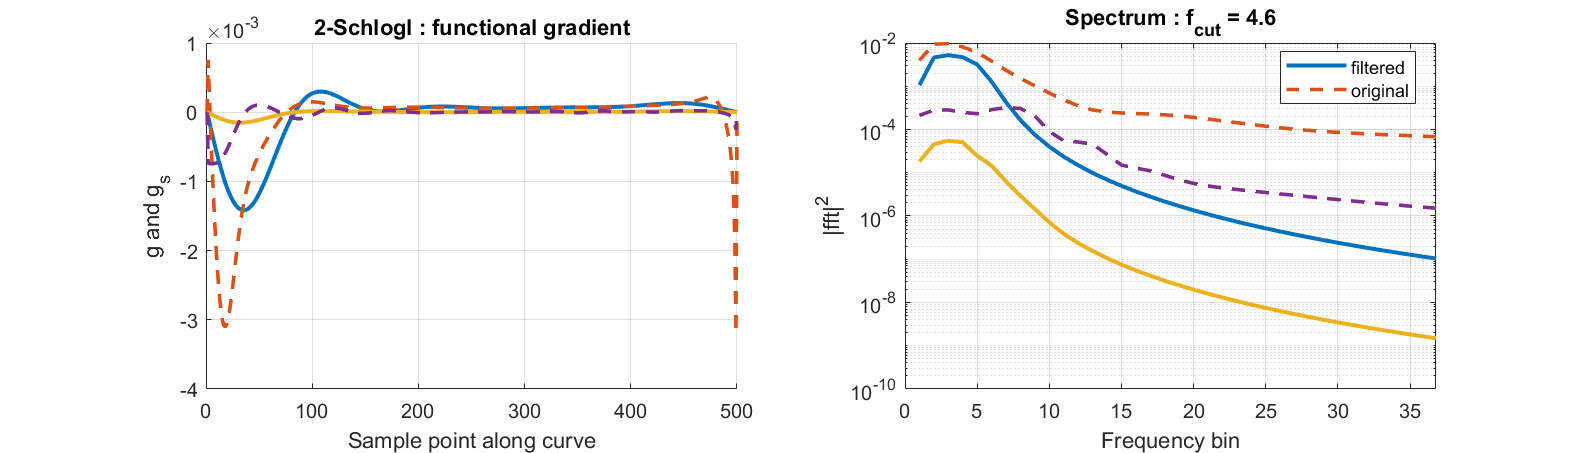

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_70.png"

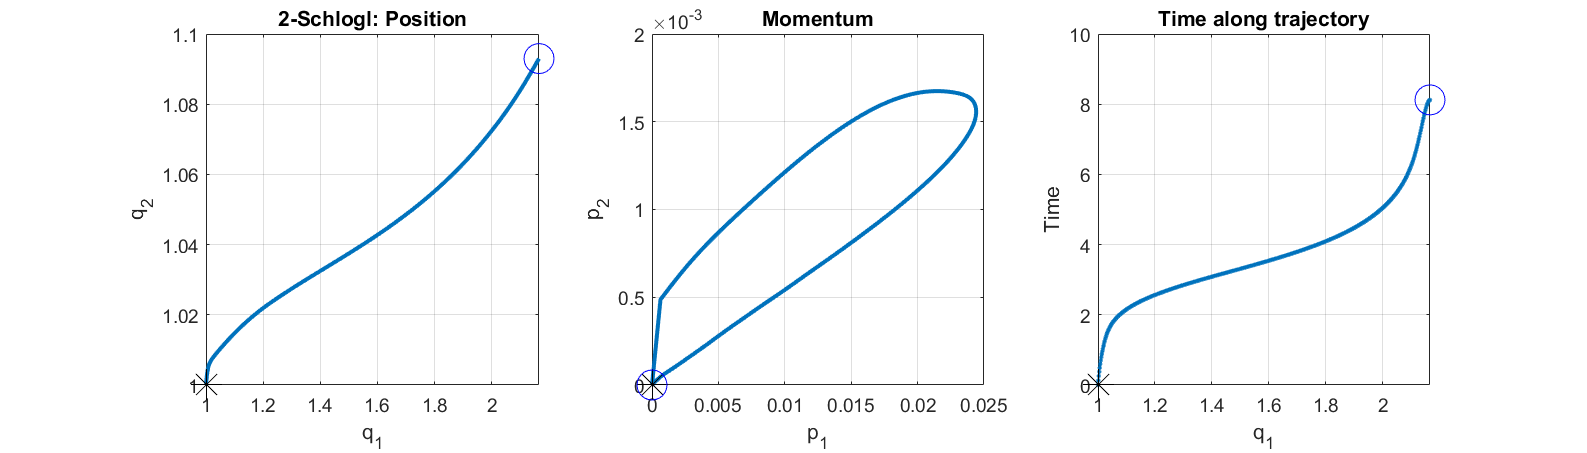

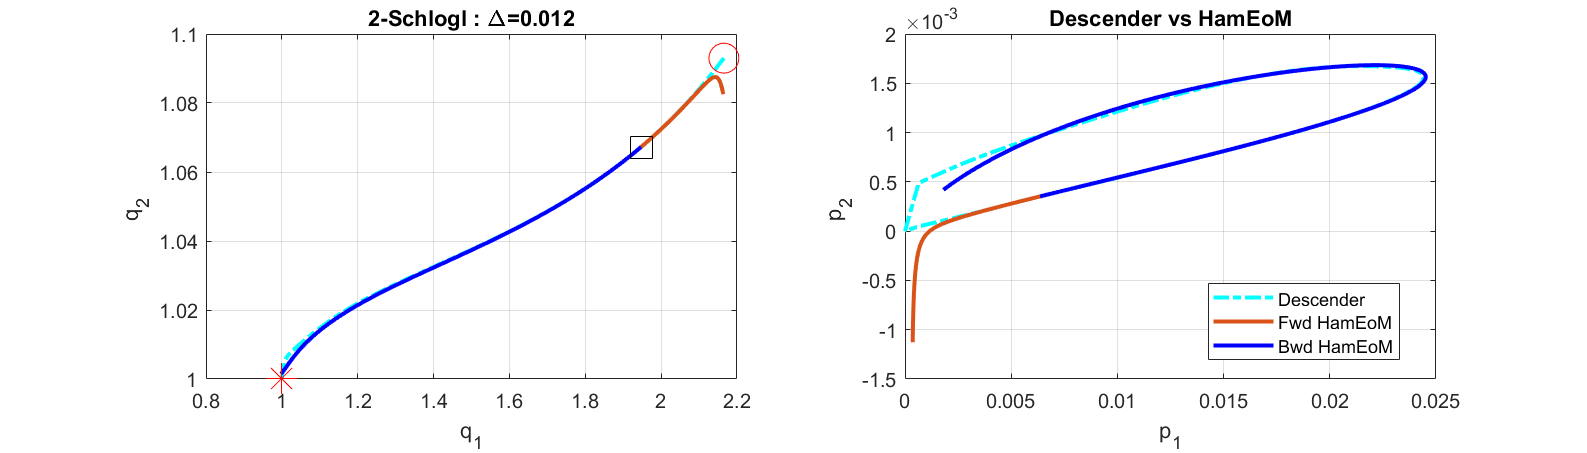

a =    0.011797183773430


delta_S =      6.604029323571681e-07


ans =   71.000000000000000   1.000000000000000   0.016808148672763   0.000000660402932   4.599999999999998


delta_S =      2.138545242592882e-07


ans =   72.000000000000000   1.000000000000000   0.016808362527287   0.000000213854524   4.599999999999998


delta_S =      2.717690433737263e-07


ans =   73.000000000000000   1.000000000000000   0.016808634296330   0.000000271769043   4.599999999999998


delta_S =      2.402036927764972e-07


ans =   74.000000000000000   1.000000000000000   0.016808874500023   0.000000240203693   4.599999999999998


delta_S =      4.934835078768129e-09


ans =   75.000000000000000   1.000000000000000   0.016808879434858   0.000000004934835   4.599999999999998


delta_S =     -9.791307574856523e-06


ans =   76.000000000000000   1.000000000000000   0.016799088127283  -0.000009791307575   4.699999999999998


delta_S =      1.376875297099539e-06


ans =   77.000000000000000   1.000000000000000   0.016800465002580   0.000001376875297   4.699999999999998


delta_S =      5.581751676527608e-06


ans =   78.000000000000000   1.000000000000000   0.016806046754257   0.000005581751677   4.699999999999998


delta_S =      2.972997190583970e-07


ans =   79.000000000000000   1.000000000000000   0.016806344053976   0.000000297299719   4.699999999999998


delta_S =      4.960142150900460e-07


ans =   80.000000000000000   1.000000000000000   0.016806840068191   0.000000496014215   4.699999999999998


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_80.png"

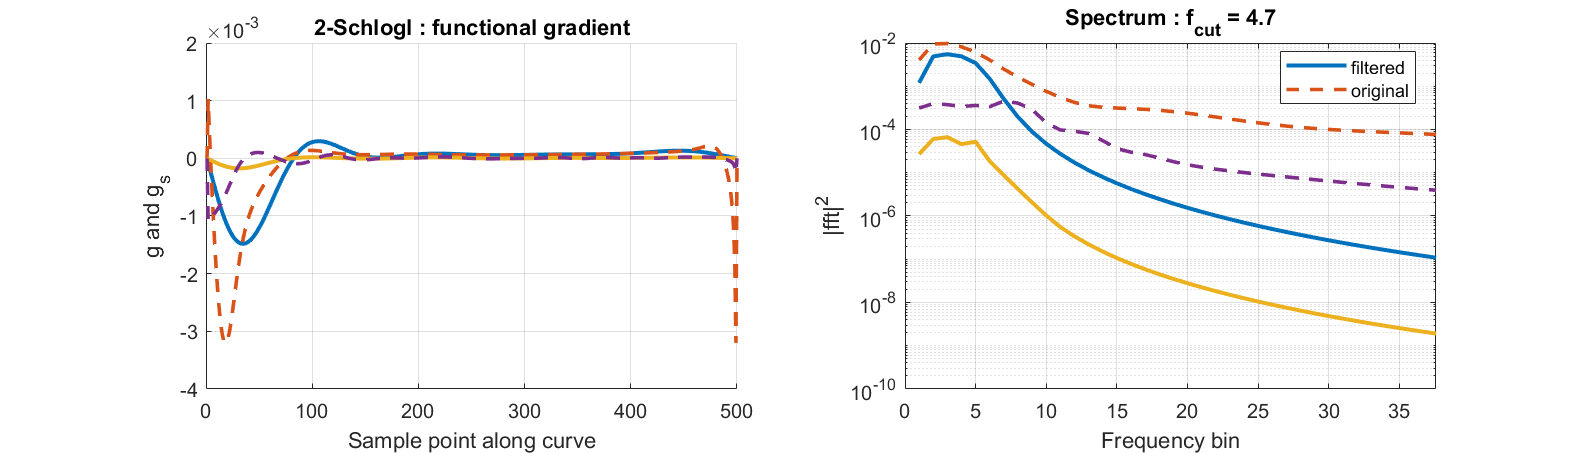

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_80.png"

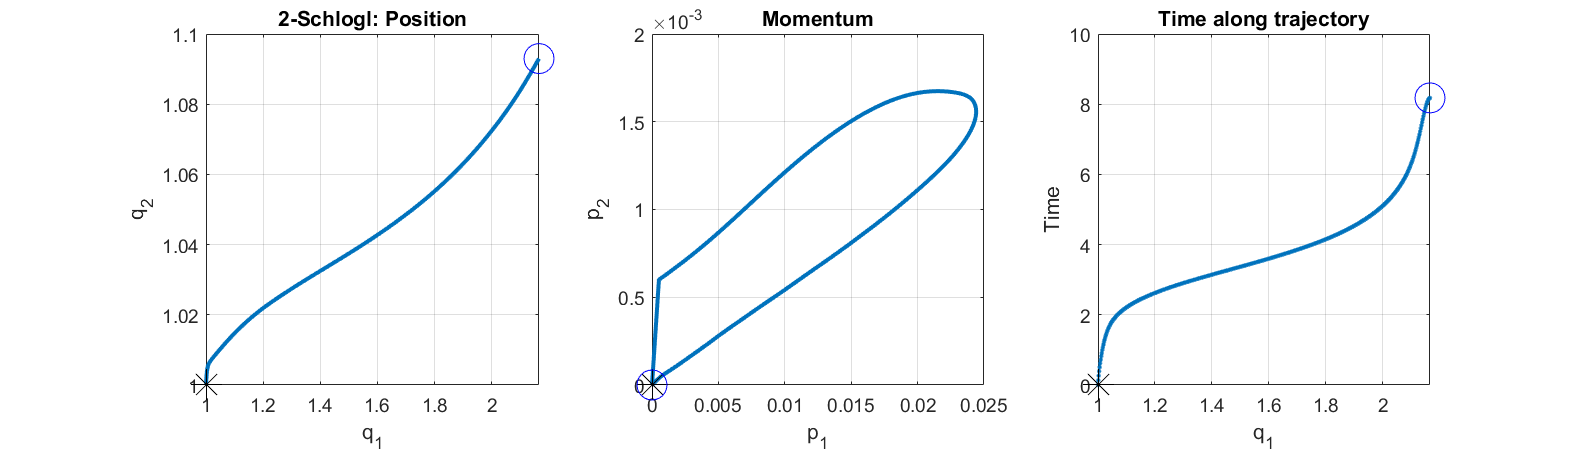

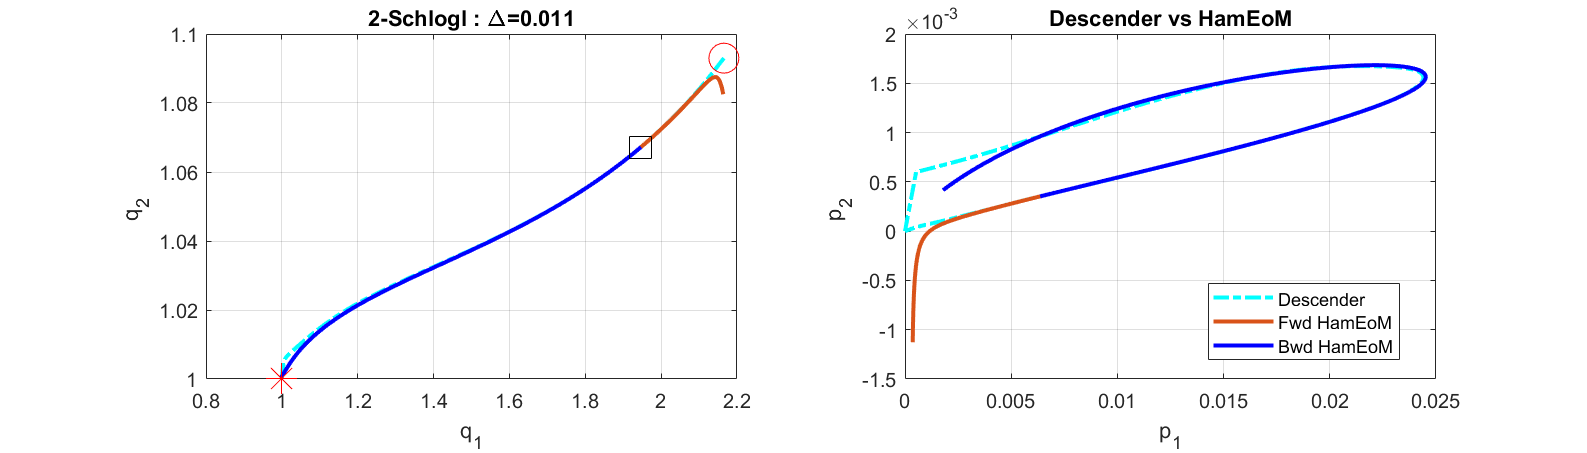

a =    0.010813459430600


delta_S =      4.086538967253139e-07


ans =   81.000000000000000   1.000000000000000   0.016807248722088   0.000000408653897   4.699999999999998


delta_S =      5.939401125434896e-07


ans =   82.000000000000000   1.000000000000000   0.016807842662200   0.000000593940113   4.699999999999998


delta_S =      2.035789292281764e-07


ans =   83.000000000000000   1.000000000000000   0.016808046241130   0.000000203578929   4.699999999999998


delta_S =      2.303775521114715e-07


ans =   84.000000000000000   1.000000000000000   0.016808276618682   0.000000230377552   4.699999999999998


delta_S =      1.536989500290631e-07


ans =   85.000000000000000   1.000000000000000   0.016808430317632   0.000000153698950   4.699999999999998


delta_S =      1.142059048372945e-07


ans =   86.000000000000000   1.000000000000000   0.016808544523537   0.000000114205905   4.699999999999998


delta_S =     -3.748620000174063e-08


ans =   87.000000000000000   1.000000000000000   0.016808507037337  -0.000000037486200   4.699999999999998


delta_S =     -8.782766804670689e-06


ans =   88.000000000000000   1.000000000000000   0.016799724270532  -0.000008782766805   4.799999999999997


delta_S =      1.260783086313999e-06


ans =   89.000000000000000   1.000000000000000   0.016800985053618   0.000001260783086   4.799999999999997


delta_S =      1.097994925831208e-06


ans =   90.000000000000000   1.000000000000000   0.016802083048544   0.000001097994926   4.799999999999997


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_90.png"

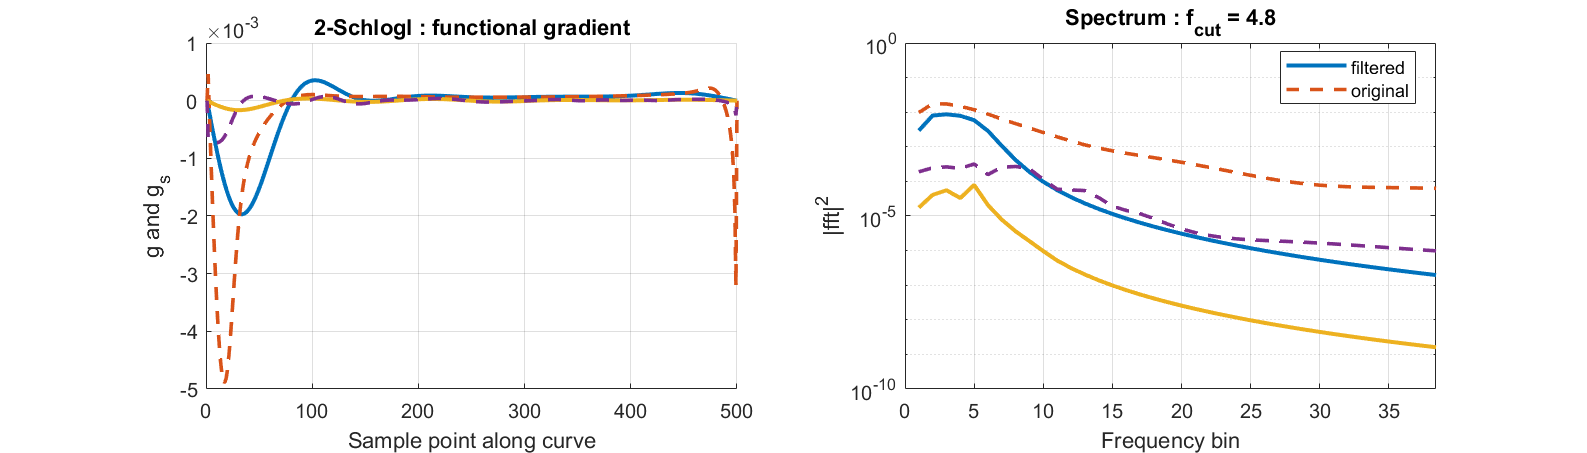

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_90.png"

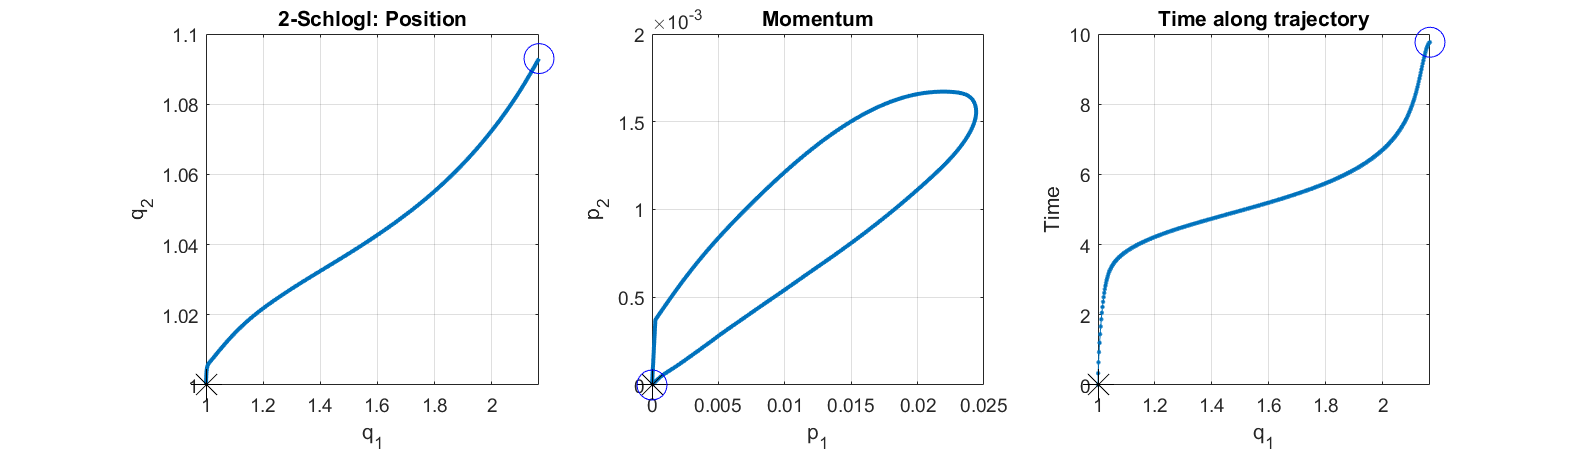

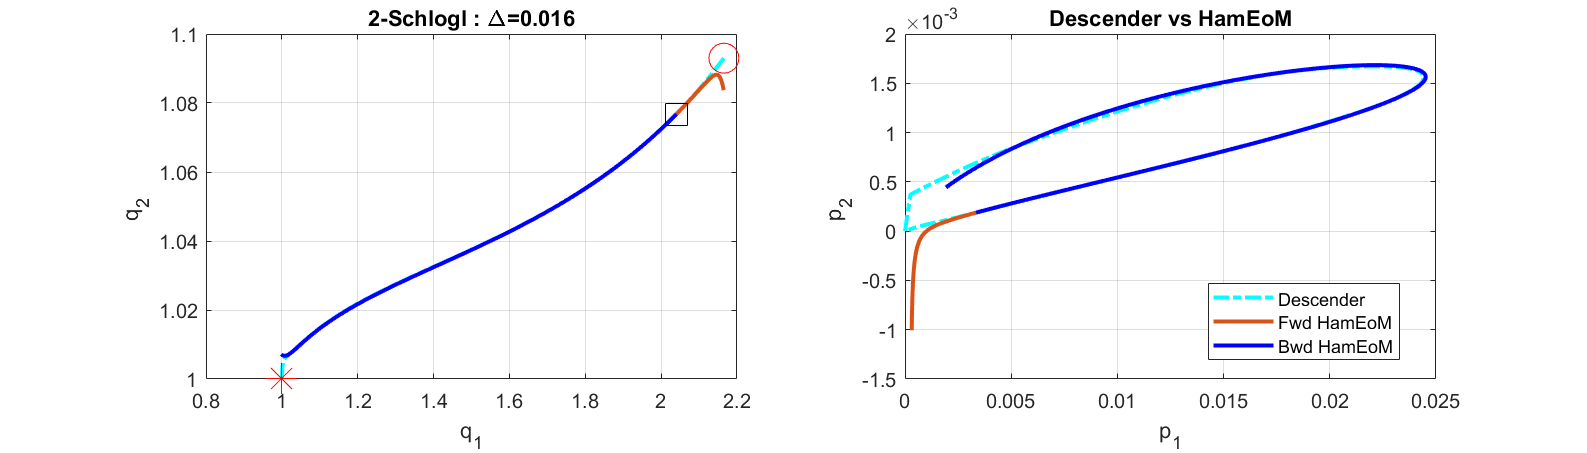

a =    0.015504682401200


delta_S =      3.610388440794532e-06


ans = 1×5
  91.000000000000000   1.000000000000000   0.016805693436985   0.000003610388441   4.799999999999997


delta_S =      4.019499836270535e-07


ans = 1×5
  92.000000000000000   1.000000000000000   0.016806095386968   0.000000401949984   4.799999999999997


delta_S =      2.727479431995083e-07


ans = 1×5
  93.000000000000000   1.000000000000000   0.016806368134912   0.000000272747943   4.799999999999997


delta_S =      2.539186240053948e-07


ans = 1×5
  94.000000000000000   1.000000000000000   0.016806622053536   0.000000253918624   4.799999999999997


delta_S =      3.248763718356751e-07


ans = 1×5
  95.000000000000000   1.000000000000000   0.016806946929907   0.000000324876372   4.799999999999997


delta_S =      3.702377414788183e-07


ans = 1×5
  96.000000000000000   1.000000000000000   0.016807317167649   0.000000370237741   4.799999999999997


delta_S =      8.129813109172823e-08


ans = 1×5
  97.000000000000000   1.000000000000000   0.016807398465780   0.000000081298131   4.799999999999997


delta_S =     -7.249024813884425e-06


ans = 1×5
  98.000000000000000   1.000000000000000   0.016800149440966  -0.000007249024814   4.899999999999997


delta_S =      1.228360234004772e-06


ans = 1×5
  99.000000000000000   1.000000000000000   0.016801377801200   0.000001228360234   4.899999999999997


delta_S =      1.109663392923066e-06


ans = 1×5
	1.0e+02 *

   1.000000000000000   0.010000000000000   0.000168024874646   0.000000011096634   0.049000000000000


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_100.png"

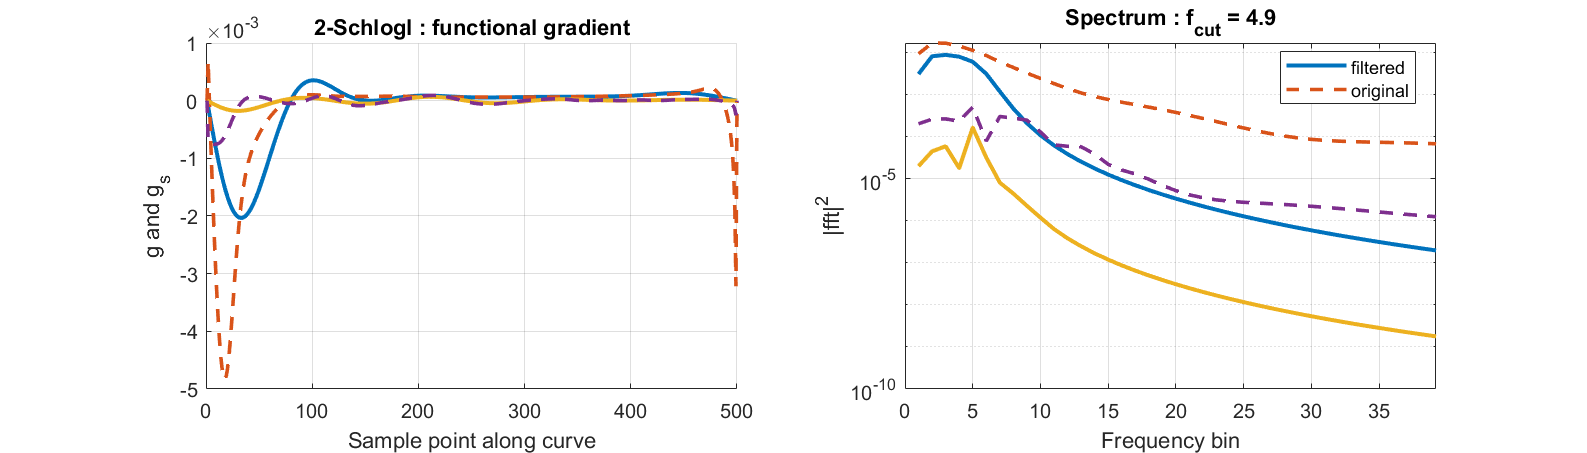

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_100.png"

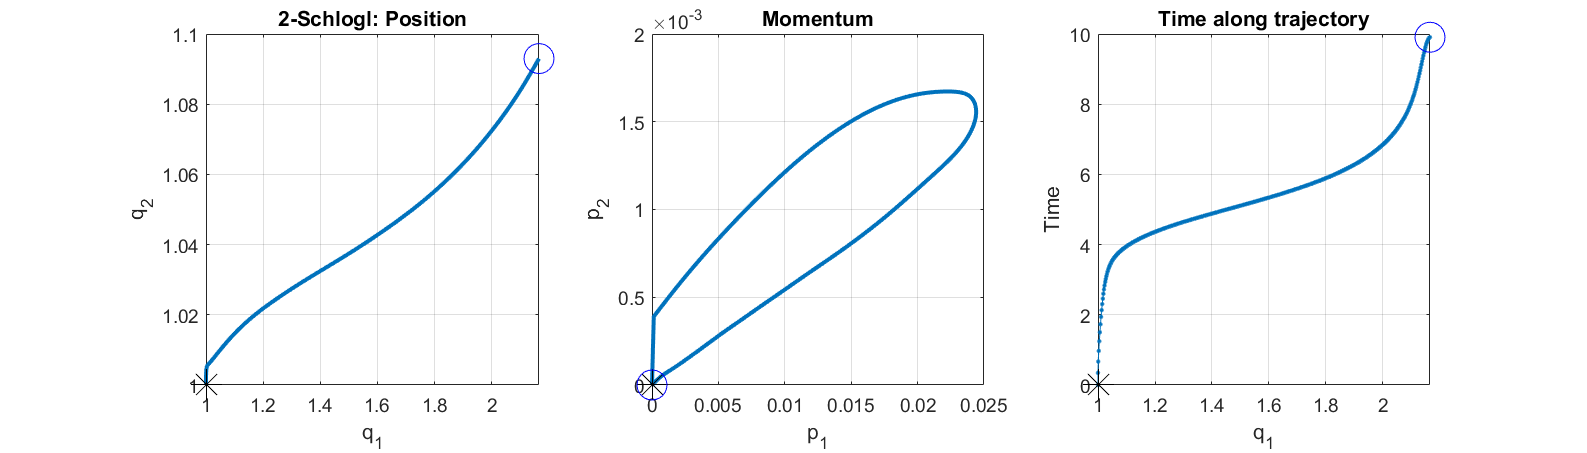

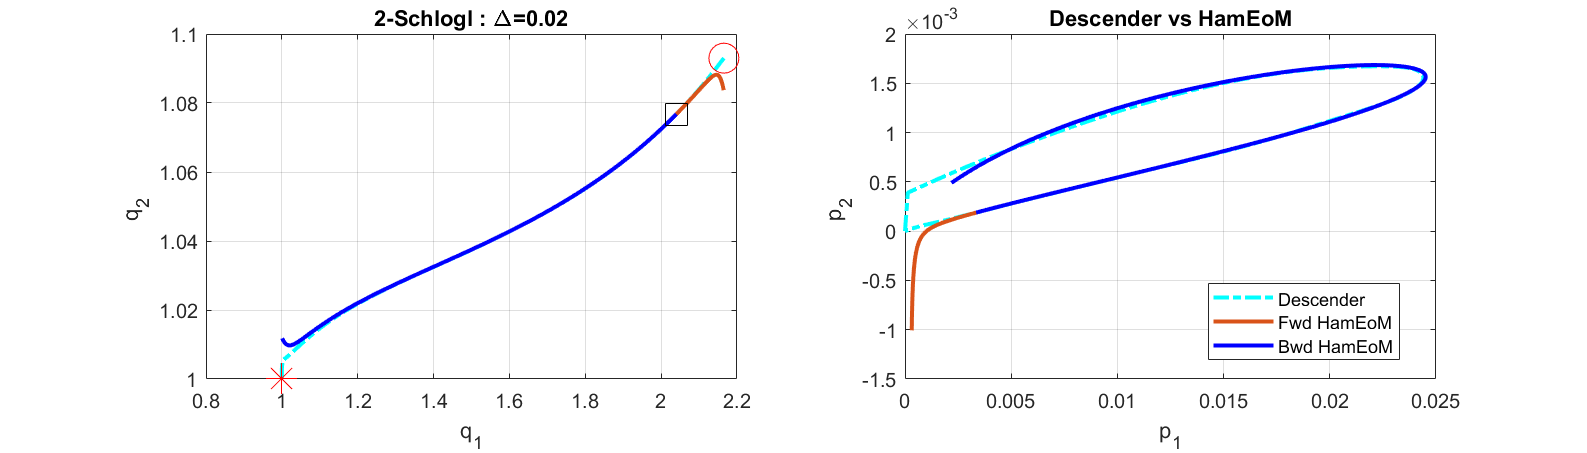

a =    0.020206793437204


delta_S =      9.112659414590996e-07


ans = 1×5
	1.0e+02 *

   1.010000000000000   0.010000000000000   0.000168033987305   0.000000009112659   0.049000000000000


delta_S =      8.286883779115573e-07


ans = 1×5
	1.0e+02 *

   1.020000000000000   0.010000000000000   0.000168042274189   0.000000008286884   0.049000000000000


delta_S =      4.921670620286478e-07


ans = 1×5
	1.0e+02 *

   1.030000000000000   0.010000000000000   0.000168047195860   0.000000004921671   0.049000000000000


delta_S =      5.749540349549165e-07


ans = 1×5
	1.0e+02 *

   1.040000000000000   0.010000000000000   0.000168052945400   0.000000005749540   0.049000000000000


delta_S =      5.662079130414055e-07


ans = 1×5
	1.0e+02 *

   1.050000000000000   0.010000000000000   0.000168058607479   0.000000005662079   0.049000000000000


delta_S =      2.198015414088539e-07


ans = 1×5
	1.0e+02 *

   1.060000000000000   0.010000000000000   0.000168060805495   0.000000002198015   0.049000000000000


delta_S =      2.612684290304035e-07


ans = 1×5
	1.0e+02 *

   1.070000000000000   0.010000000000000   0.000168063418179   0.000000002612684   0.049000000000000


delta_S =      5.992502376261921e-09


ans = 1×5
	1.0e+02 *

   1.080000000000000   0.010000000000000   0.000168063478104   0.000000000059925   0.049000000000000


delta_S =     -4.647633690228747e-06


ans = 1×5
	1.0e+02 *

   1.090000000000000   0.010000000000000   0.000168017001767  -0.000000046476337   0.050000000000000


delta_S =      1.207428356915508e-06


ans = 1×5
	1.0e+02 *

   1.100000000000000   0.010000000000000   0.000168029076051   0.000000012074284   0.050000000000000


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_110.png"

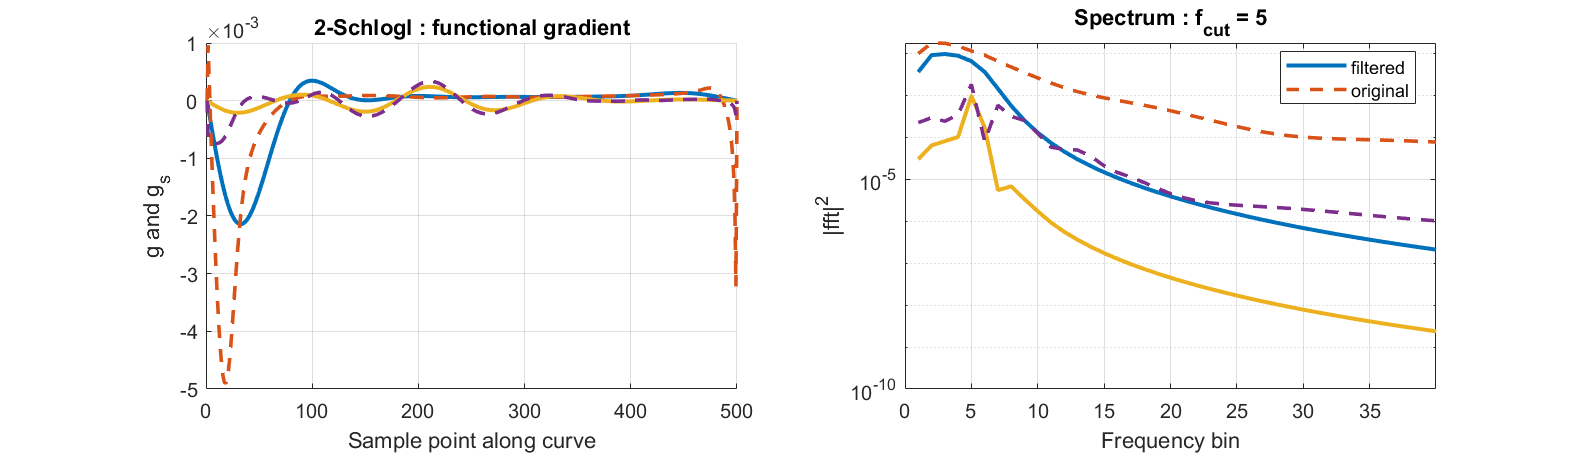

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_110.png"

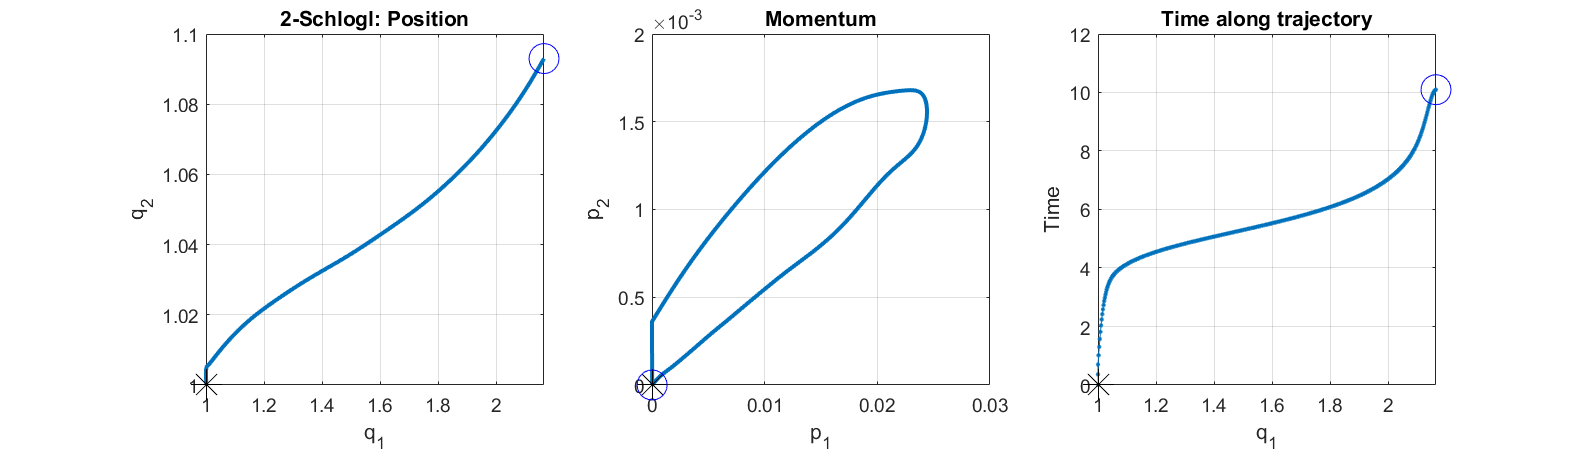

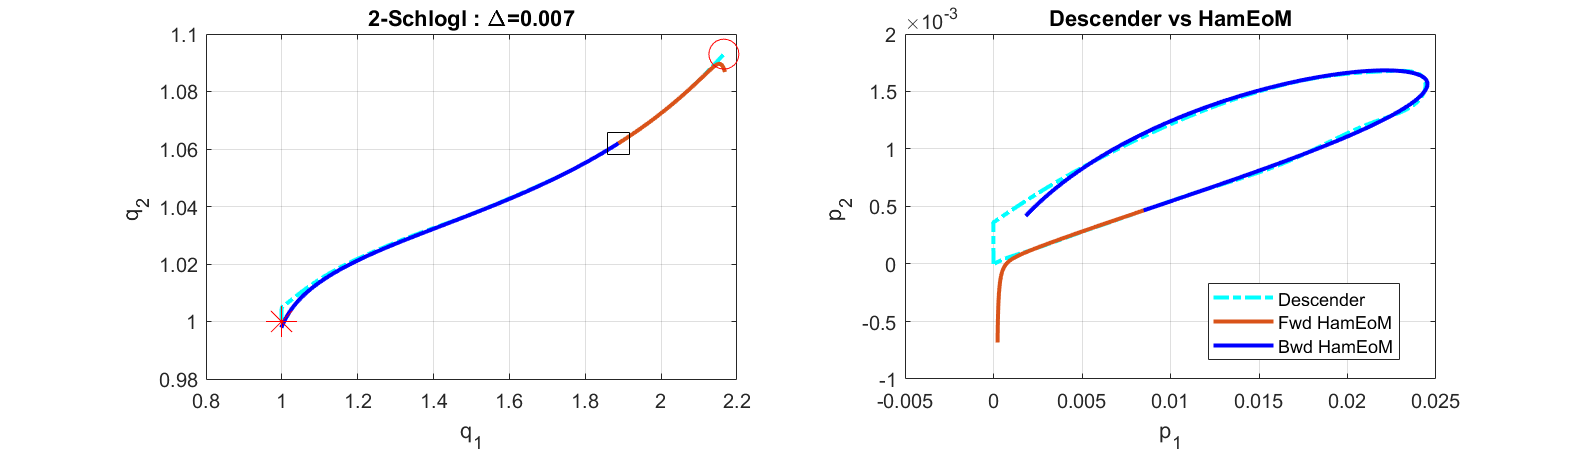

a =    0.006501045492706


delta_S =      8.857682533246203e-07


ans = 1×5
	1.0e+02 *

   1.110000000000000   0.010000000000000   0.000168037933733   0.000000008857683   0.050000000000000


delta_S =      1.030574354448505e-06


ans = 1×5
	1.0e+02 *

   1.120000000000000   0.010000000000000   0.000168048239477   0.000000010305744   0.050000000000000


delta_S =      8.206596890138196e-07


ans = 1×5
	1.0e+02 *

   1.130000000000000   0.010000000000000   0.000168056446074   0.000000008206597   0.050000000000000


delta_S =      7.101559832446702e-07


ans = 1×5
	1.0e+02 *

   1.140000000000000   0.010000000000000   0.000168063547633   0.000000007101560   0.050000000000000


delta_S =      4.815823931719754e-07


ans = 1×5
	1.0e+02 *

   1.150000000000000   0.010000000000000   0.000168068363457   0.000000004815824   0.050000000000000


delta_S =      3.290760741334053e-07


ans = 1×5
	1.0e+02 *

   1.160000000000000   0.010000000000000   0.000168071654218   0.000000003290761   0.050000000000000


delta_S =      4.223395983597722e-07


ans = 1×5
	1.0e+02 *

   1.170000000000000   0.010000000000000   0.000168075877614   0.000000004223396   0.050000000000000


delta_S =      1.562050510779678e-07


ans = 1×5
	1.0e+02 *

   1.180000000000000   0.010000000000000   0.000168077439665   0.000000001562051   0.050000000000000


delta_S =     -2.245365626069029e-08


ans = 1×5
	1.0e+02 *

   1.190000000000000   0.010000000000000   0.000168077215128  -0.000000000224537   0.050000000000000


delta_S =     -2.569900175046491e-06


ans = 1×5
	1.0e+02 *

   1.200000000000000   0.010000000000000   0.000168051516126  -0.000000025699002   0.051000000000000


save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_deltax_120.png"

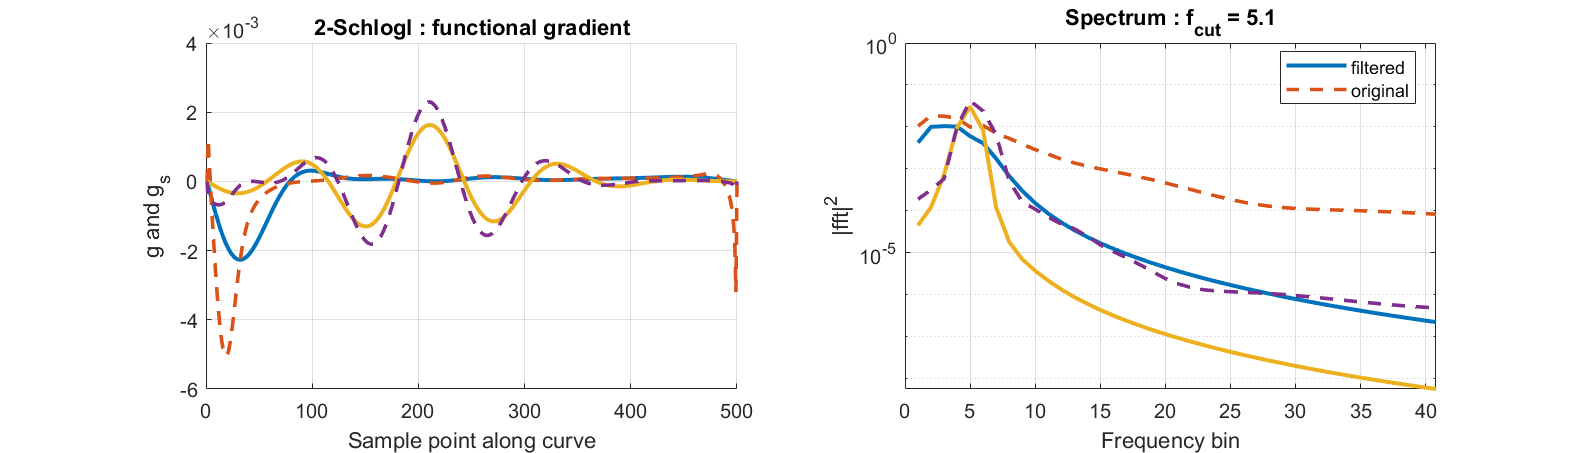

save_plot_name = "Plots/Schlogl_1_2_1_2_500_11-Jul-2022_PS_traj_120.png"

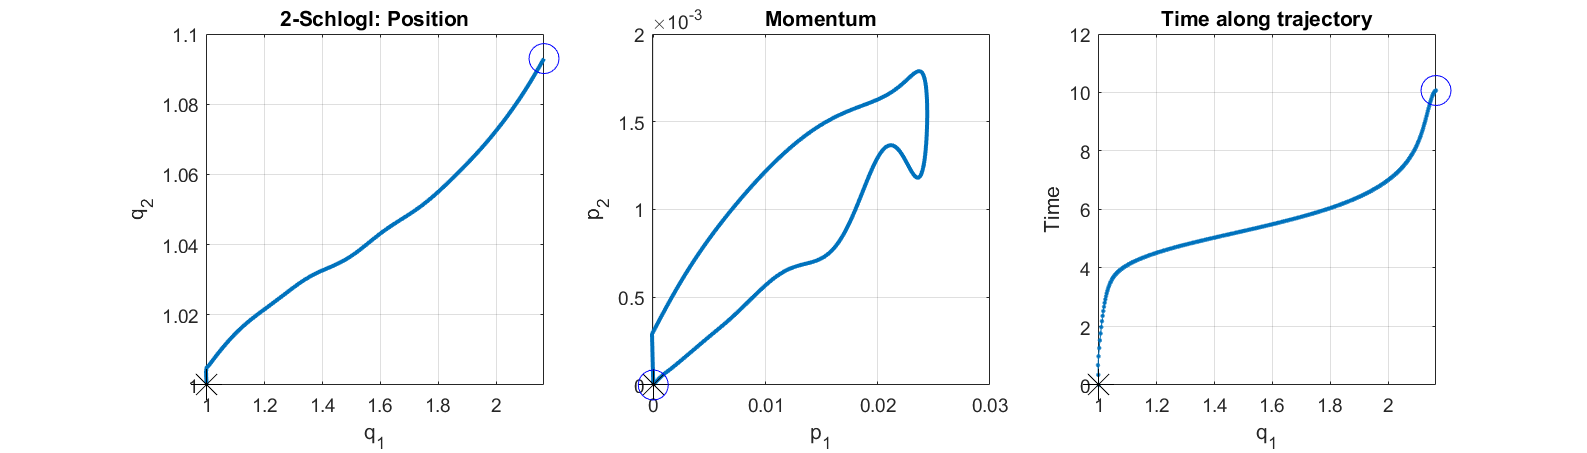

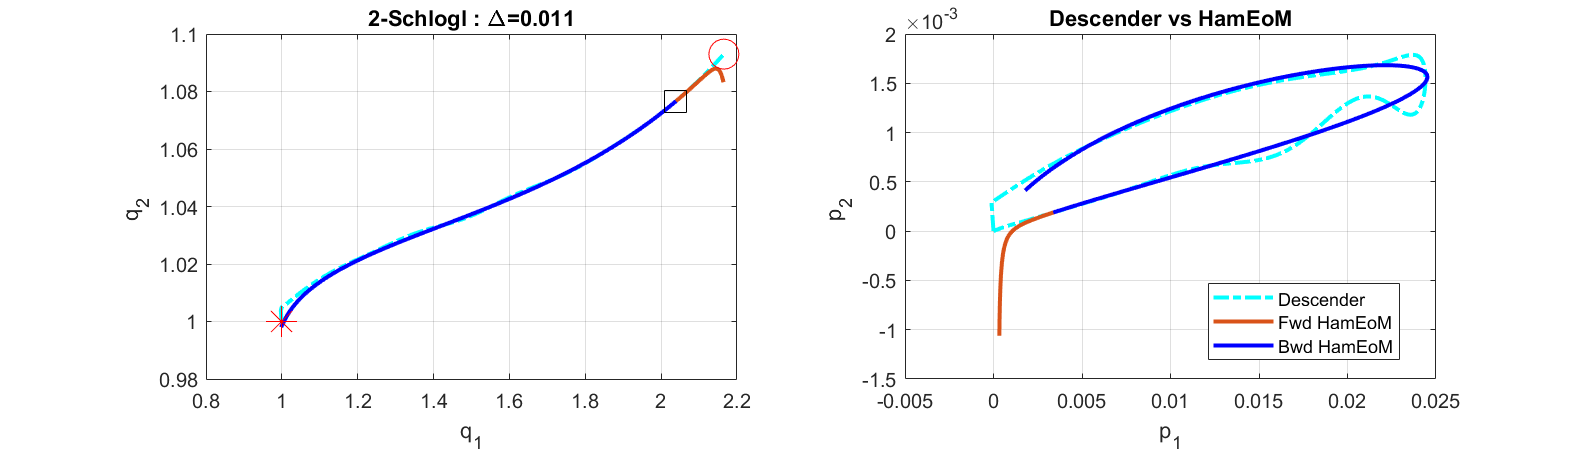

a =    0.010546442624799


format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max && a>a_min
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    if f0 >= f0_init + 1                %anneal
        f0_init = f0; f0 = f0; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        traj_pts_new = traj_pts+1000;
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

    elseif abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,10)==0
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter);
        a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end

    
end

format short


#### Look for a settiing which works

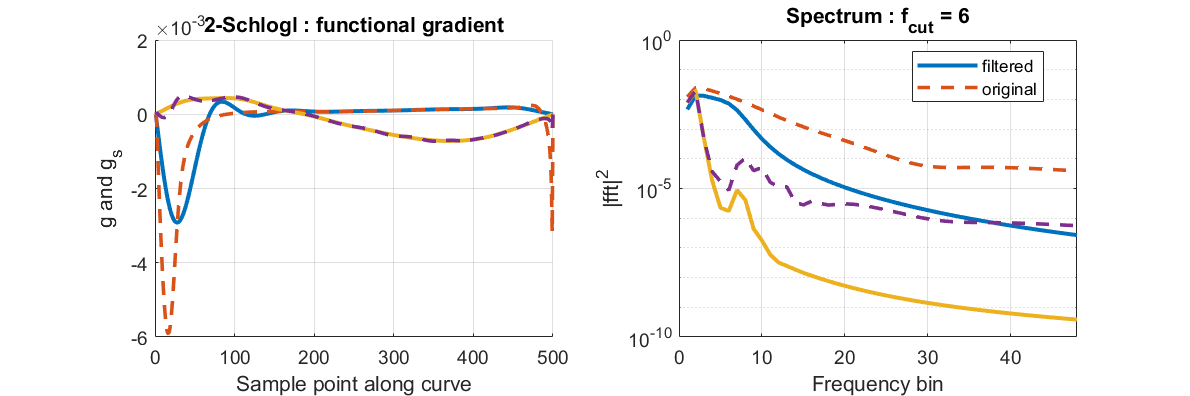

format long
f0 = 6; eps_min = 0.001;eps = 0.5;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);

delta_S =      7.119623560098709e-04


delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

ans =   26.000000000000000   0.500000000000000   0.016800152640389   0.000711962356010   6.000000000000000


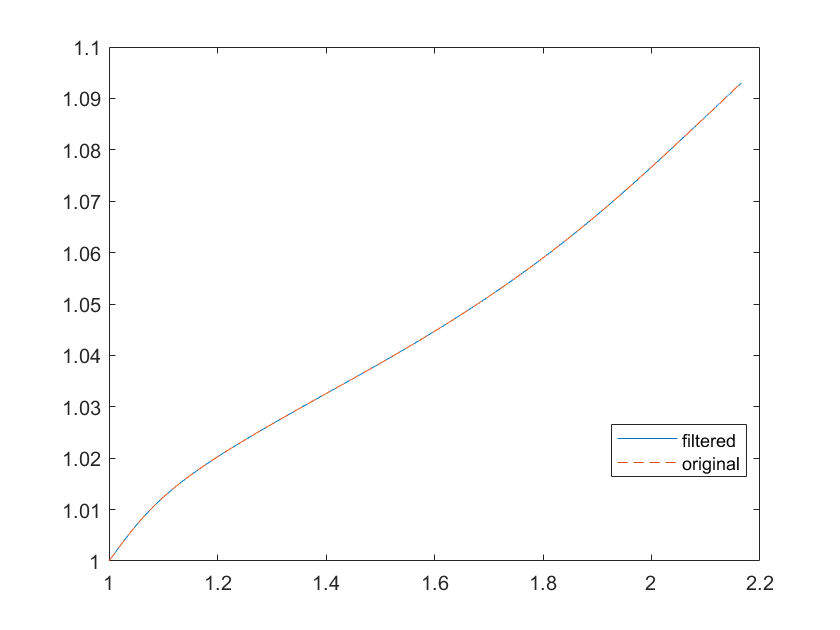

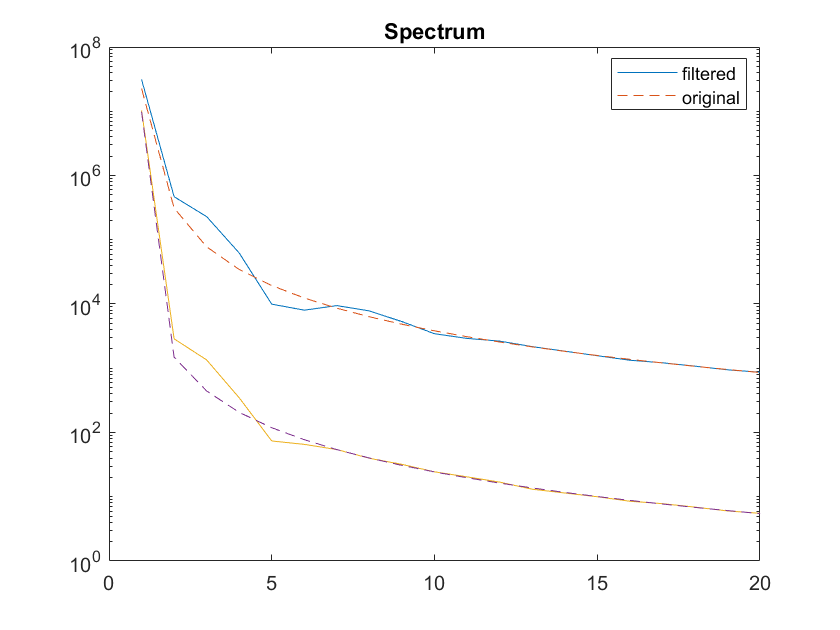

traj_pts_new = 3000;
traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);

%[traj,len_curve_prime] = space_uniform_sampling(traj_n_s,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

f0 = 6; eps_min = 0.03;eps = 0.1;
delta_x_s =  smooth_traj_butter(delta_x,f0); 
[eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
    (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min);
delta_S = action_S_new - action_S;
[iter, eps, action_S_new, delta_S, f0]

ans =   20.000000000000000                   0   0.016088190284380                   0   6.000000000000000


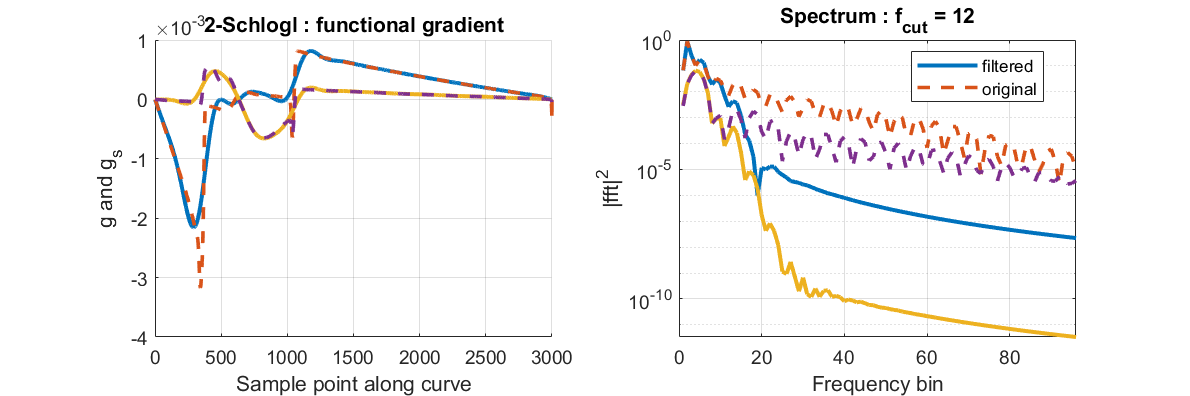

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

save_plot_name = "Plots/Schlogl_1_2_1_2_2000_11-Jul-2022_35_HamEoM_1711.png"

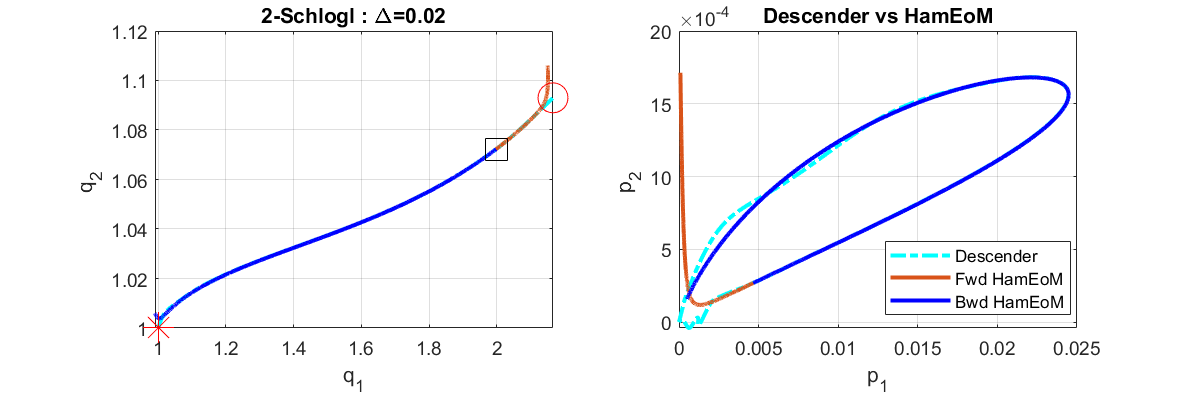

a =    0.020095655946439


iter = 35;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,iter);
S_traj = picker_arr_idx(S_traj_arr,traj_pt_arr,iter);
t_traj = picker_arr_idx(time_arr,traj_pt_arr,iter);
save_plot_name = save_plot_name_root + '_' + string(iter) + '_HamEoM';

a = Ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)


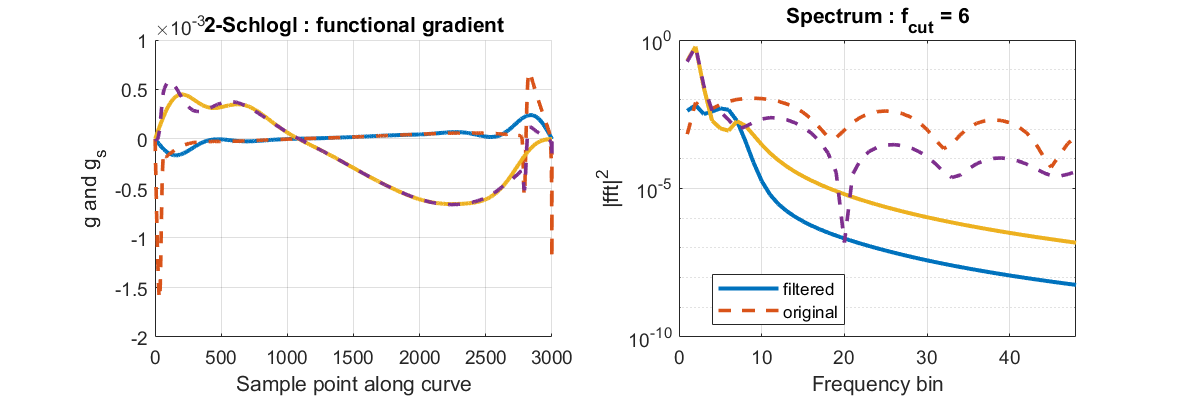

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

## Plot descent progress

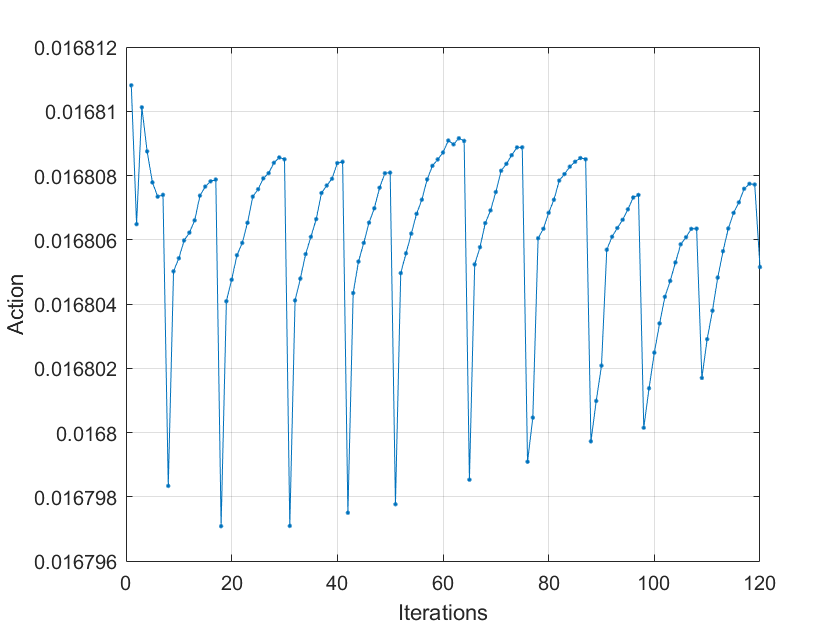

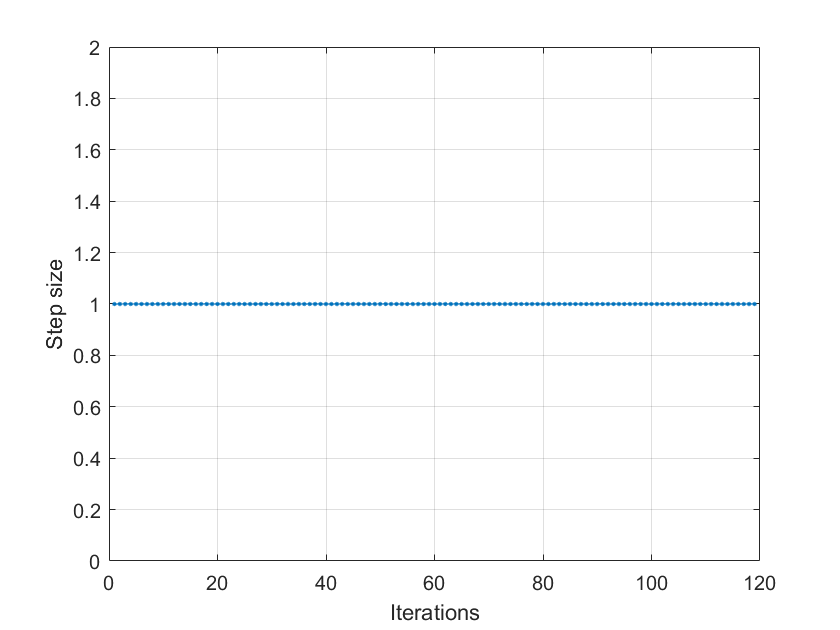

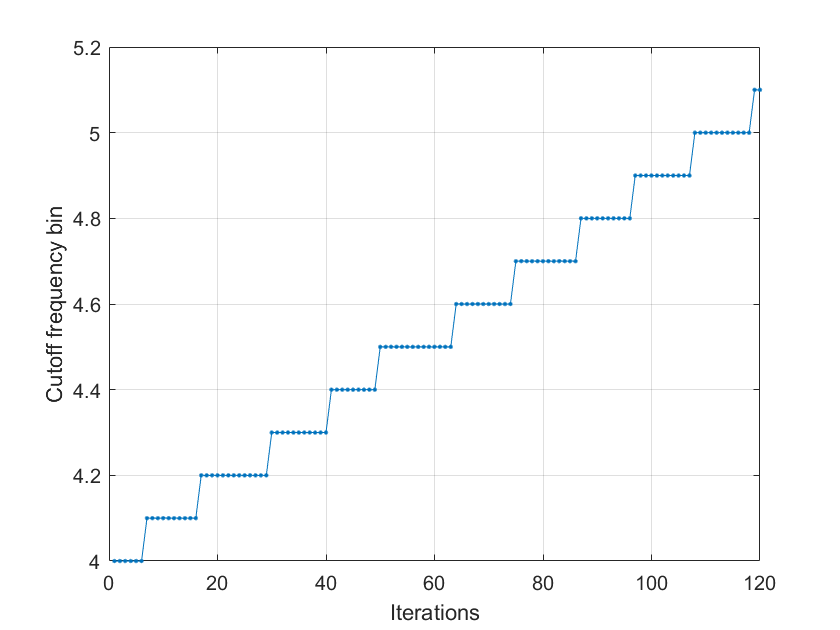

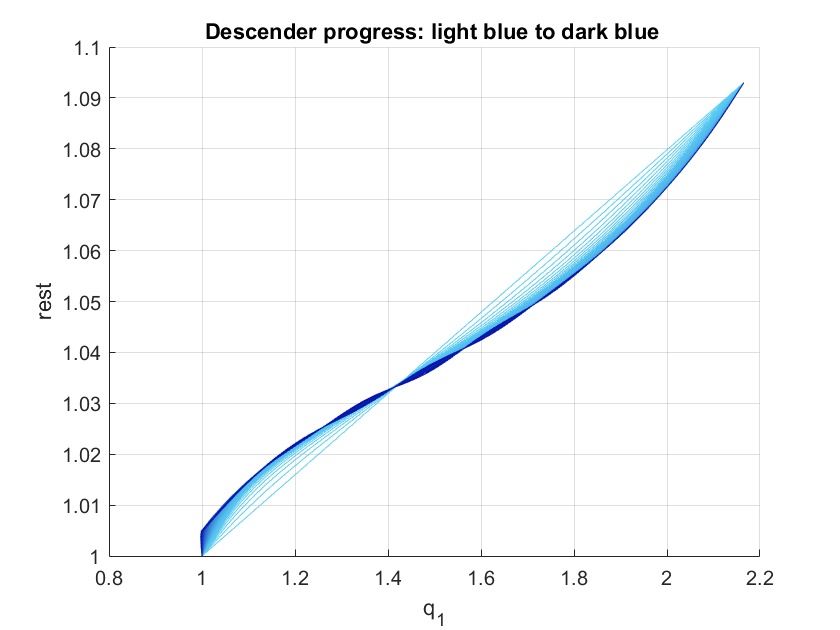

Not enough input arguments.

Error in surf_input (line 5)
fun3d = zeros(num_spec,traj_pts_indx,tot_iter);

Error in plot_everything_1 (line 56)
[deltax_3d, deltax_3d_fft] = surf_input(deltax_arr,num_spec,traj_pts,tot_iter);

plot_everything_1

f0 = 5; delta_x_s =  smooth_traj_butter(delta_x,f0); 

choose_iter = iter-1; f0 = 2;
PS_traj  = picker_arr_idx(PS_arr,traj_pt_arr,choose_iter);
delta_x_s = picker_arr_idx(deltax_lp_arr,traj_pt_arr,choose_iter);


iter_max = 24;f0 = 0.5;eps = 0.0001;

iter_max = 57;f0 = 2;

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,100);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,45);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
figure()
plot(PS_traj(:,3),PS_traj(:,4))

figure()
semilogy(abs(fft(traj_n_s)).^2)
hold on
semilogy(abs(fft(traj)).^2,'--')
hold off
xlim([0 20])

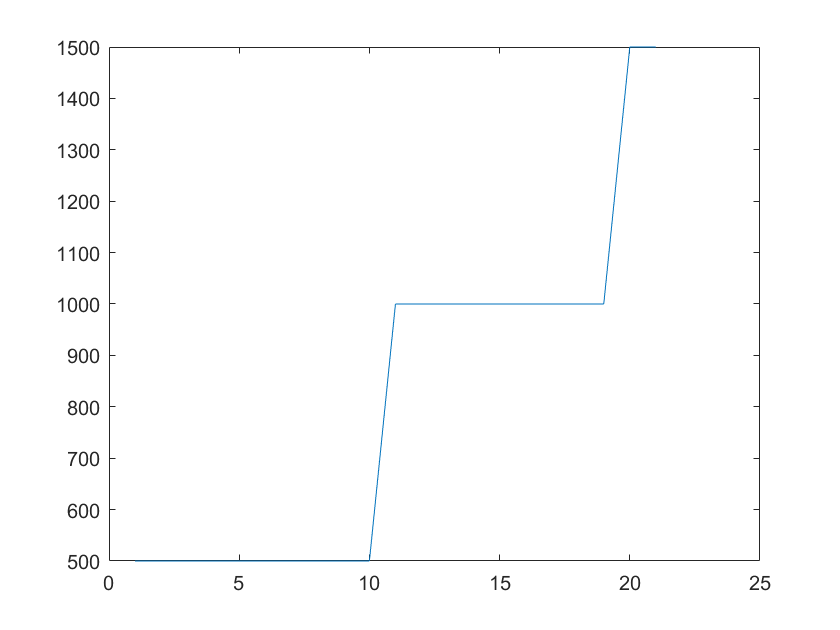

figure()
plot(traj_pt_arr)

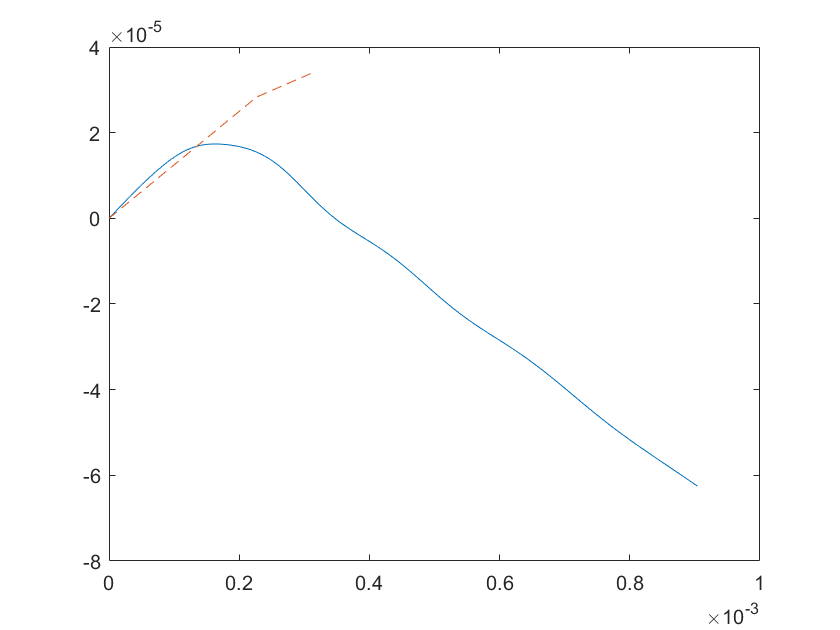

figure()
plot(PS_traj(end-200:end,3),PS_traj(end-200:end,4))
hold on
plot(PS_traj(1:5,3),PS_traj(1:5,4),'--')
hold off

size(time_arr)

ans =        24500           1


traj_pt_arr;

idx = 40;
cum_traj = [0 ;cumsum(traj_pt_arr)];
time_arr(cum_traj(idx-1)+1:cum_traj(idx),:)

ans =          0
    0.8724
    1.6732
    2.4046
    3.0676
    3.6647
    4.1986
    4.6726
    5.0905
    5.4564


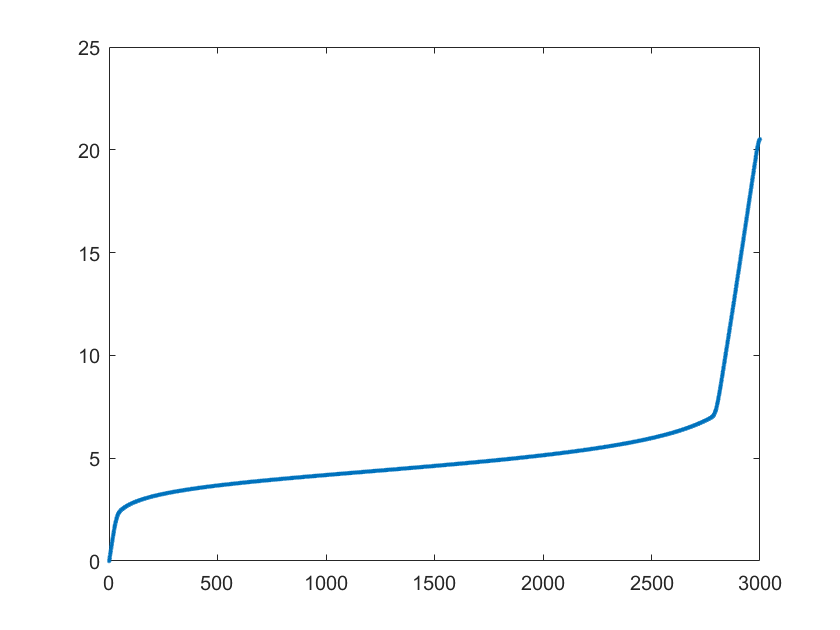

figure()
plot(t_traj,'.')

ans = 	1.0e+-3 *

    0.2214    0.0411
    0.2556    0.0455
    0.2899    0.0499
    0.3242    0.0543
    0.3585    0.0588


ans = 	1.0e+-4 *

    0.4168    0.0646
    0.3152    0.0493
    0.2114    0.0333
    0.1068    0.0170
         0         0


ans =     0.0692
    0.0692
    0.0691
    0.0691
    0.0690


ans =     0.0232
    0.0176
    0.0119
    0.0060
         0


ans = 	1.0e+-3 *

         0         0
    0.2385    0.0433
    0.2728    0.0477
    0.3071    0.0521
    0.3414    0.0565


ans = 	1.0e+-4 *

    0.4663    0.0719
    0.3660    0.0570
    0.2633    0.0413
    0.1591    0.0252
         0         0


ans =     0.0692
    0.0691
    0.0691
    0.0691
    0.0690


ans =     0.0310
    0.0259
    0.0204
    0.0148
    0.0090


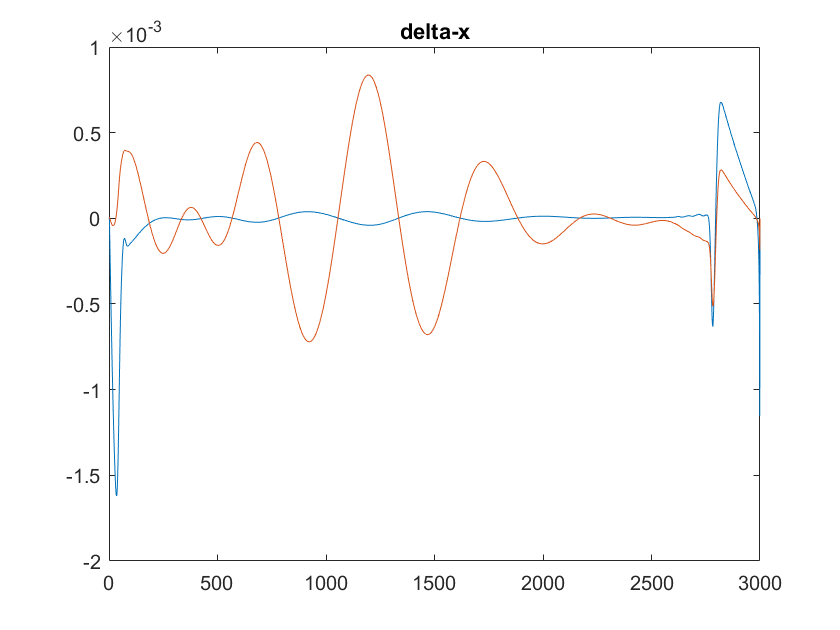

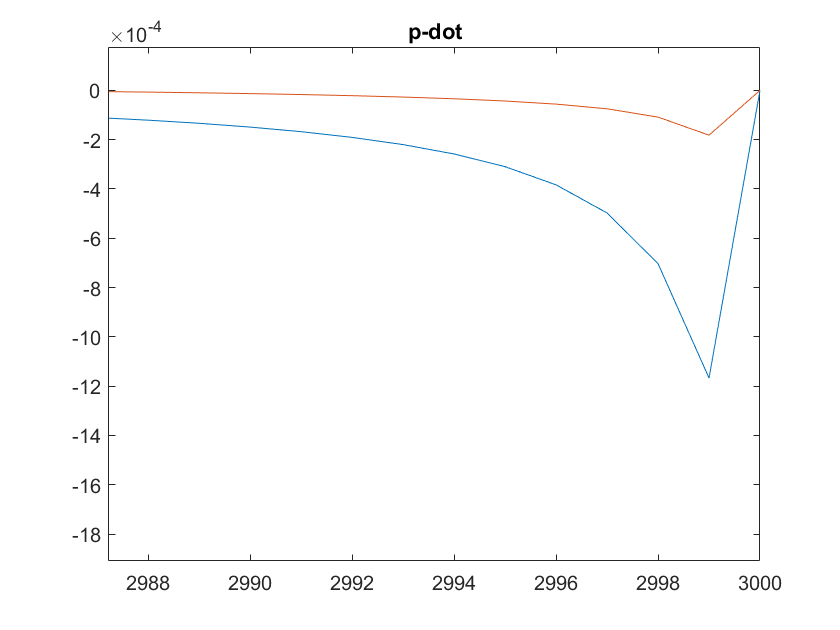

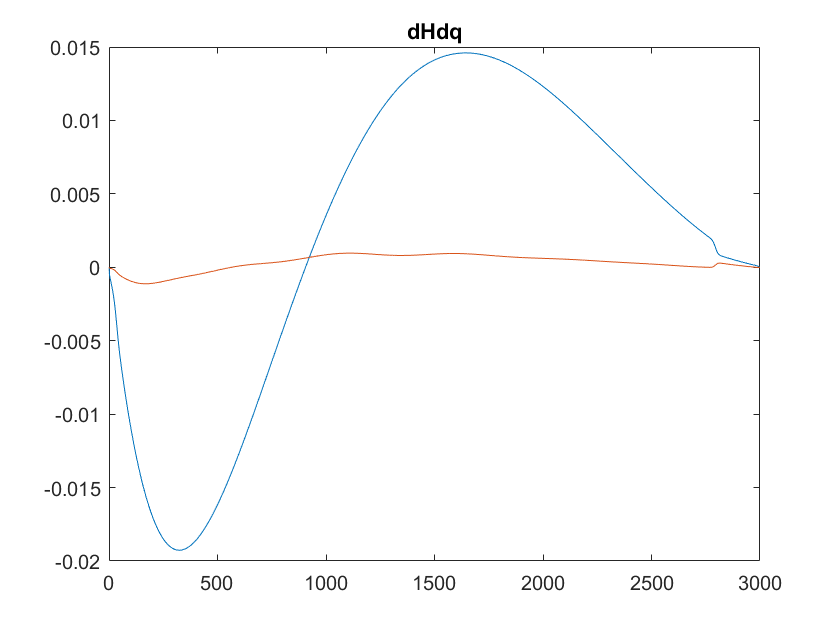

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

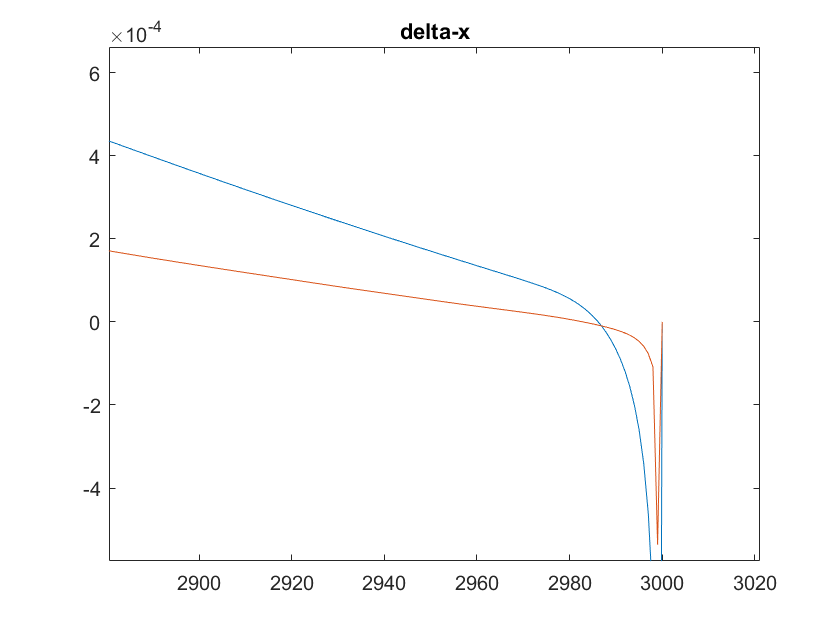

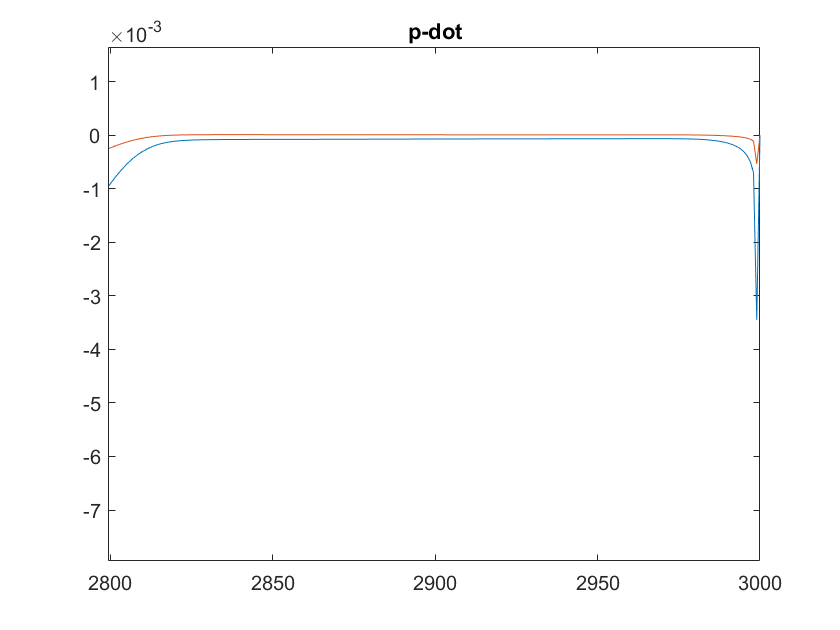

num_smooth = 45;
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

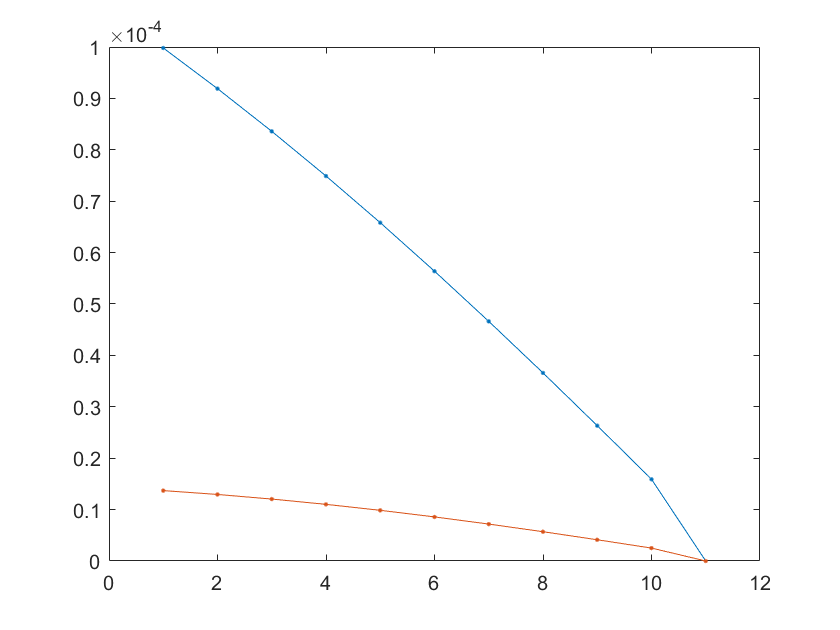

figure()
plot(PS_traj(end-10:end,3:4),'.-')

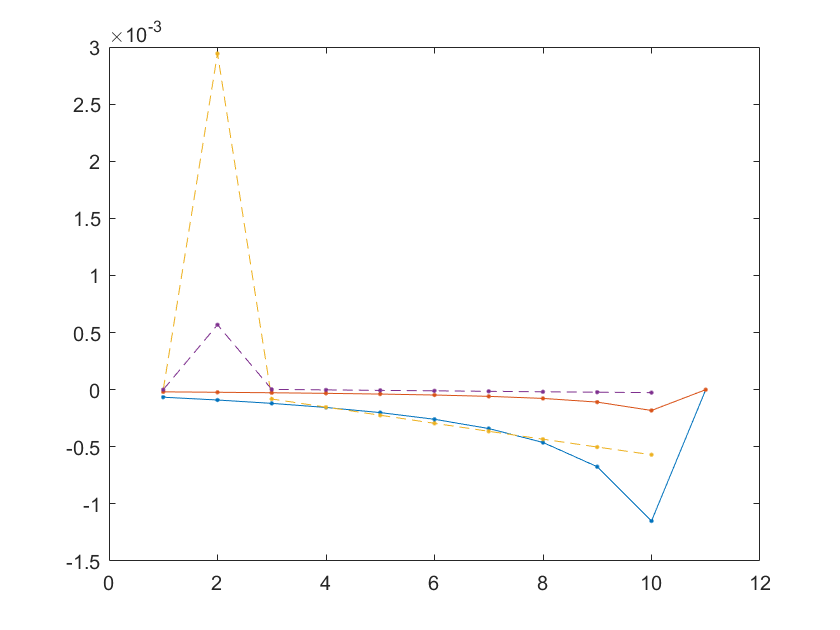

figure()
plot(delta_x(end-10:end,:),'.-')
hold on
plot(delta_x(1:10,:),'.--')
hold off

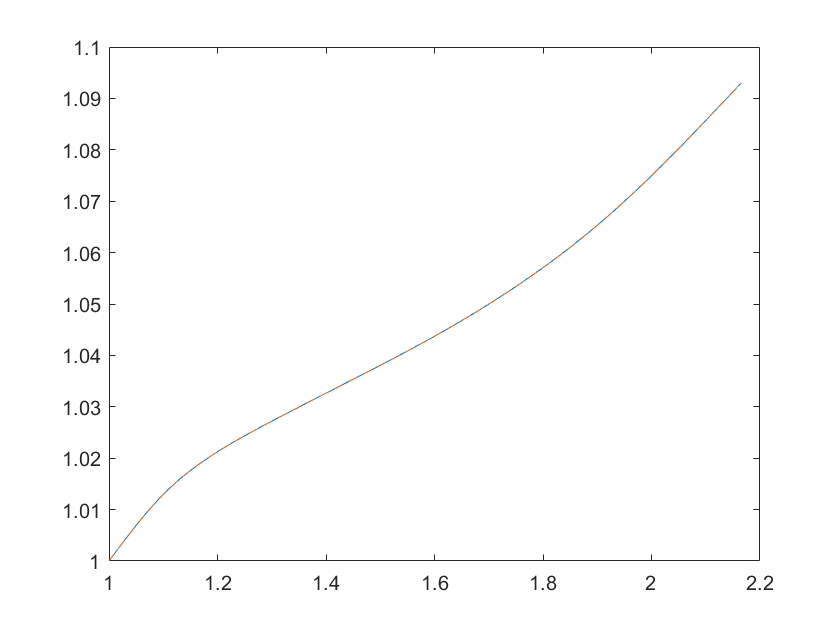

traj_pts_new = traj_pts+1000;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new,35);

%Plot PS_traj and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_PS_traj50.png"

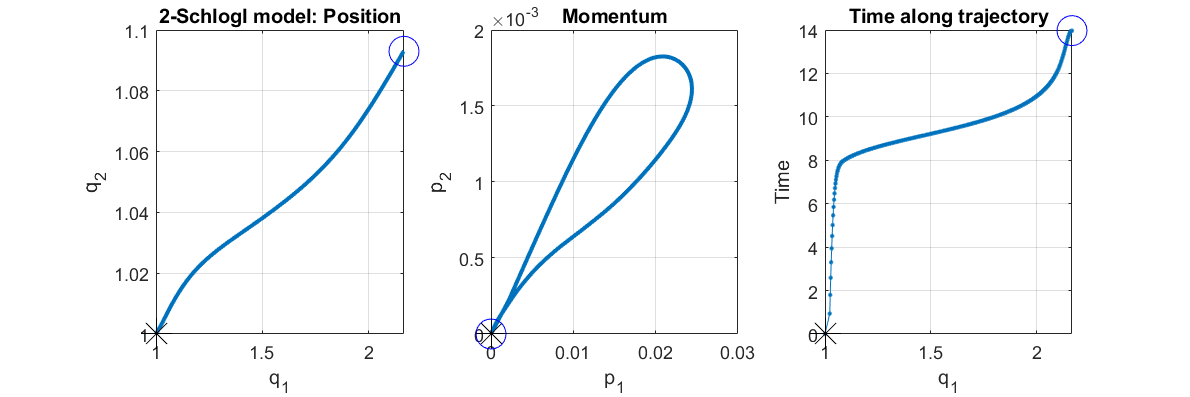

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax14.png"

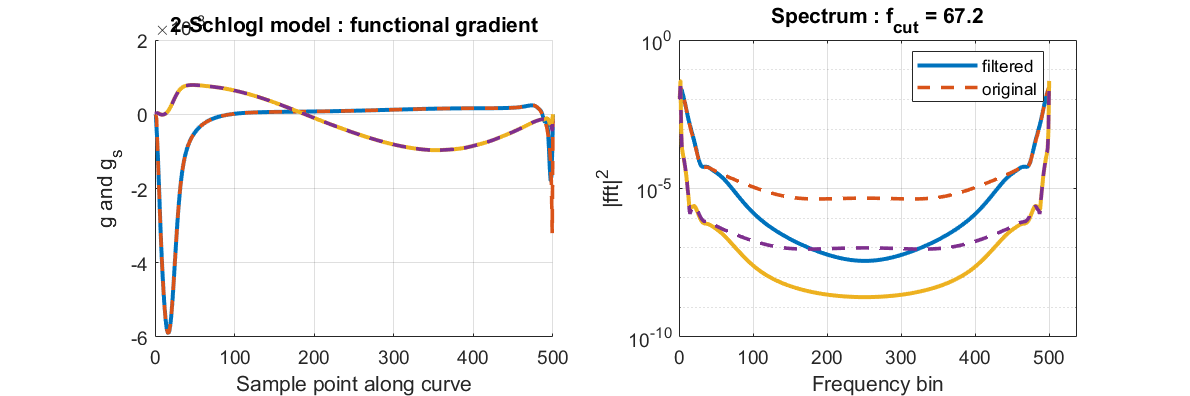

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax106.png"

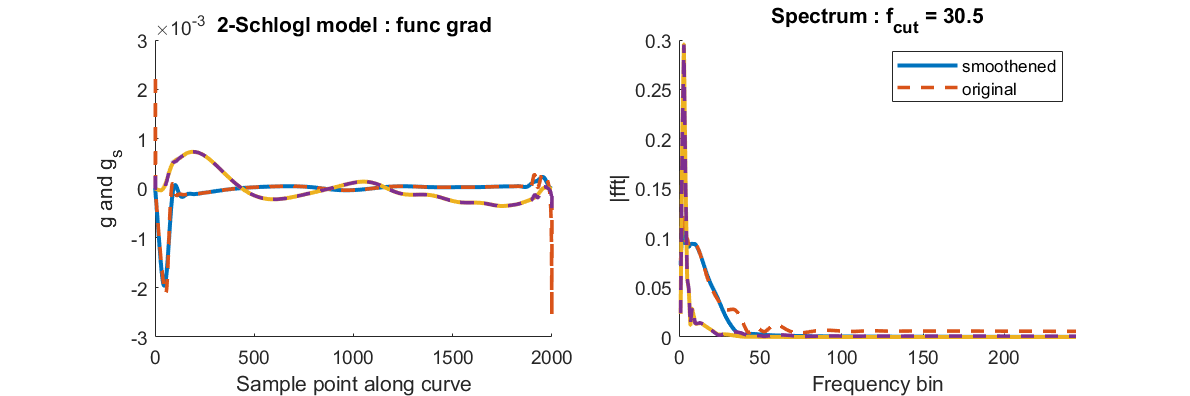

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

%Plot delta_x and save
save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_deltax'+string(iter)+'.png'

save_plot_name = "Plots/Schlogl_1_2_1_2_deltax109.png"

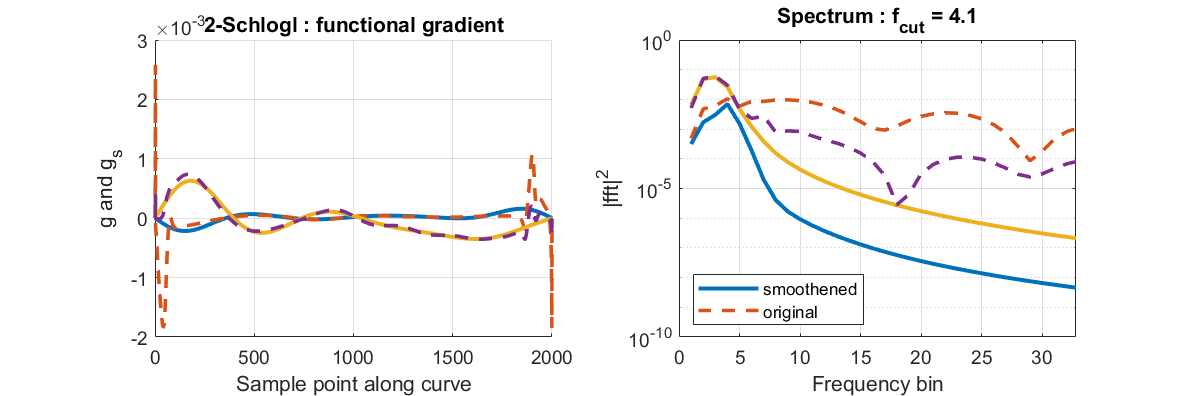

debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);

savenam

savenam = "..\Data\Schlogl_1_2_descend_1_2straight_2000_09-Jul-2022.mat"

delta_x(3,:)

ans = 	1.0e+-3 *

   -0.0681    0.1228


[traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);


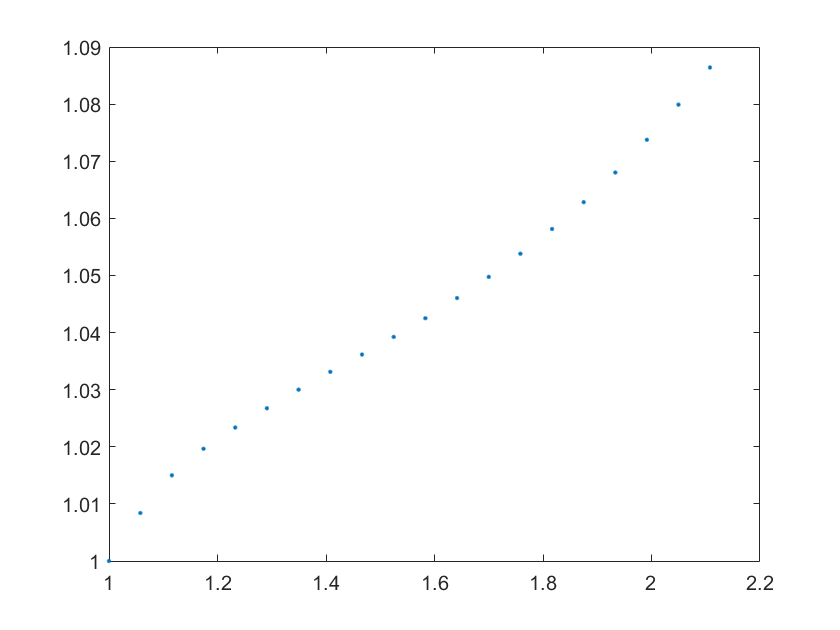

figure()
plot(traj(1:100:end,1),traj(1:100:end,2),'.')

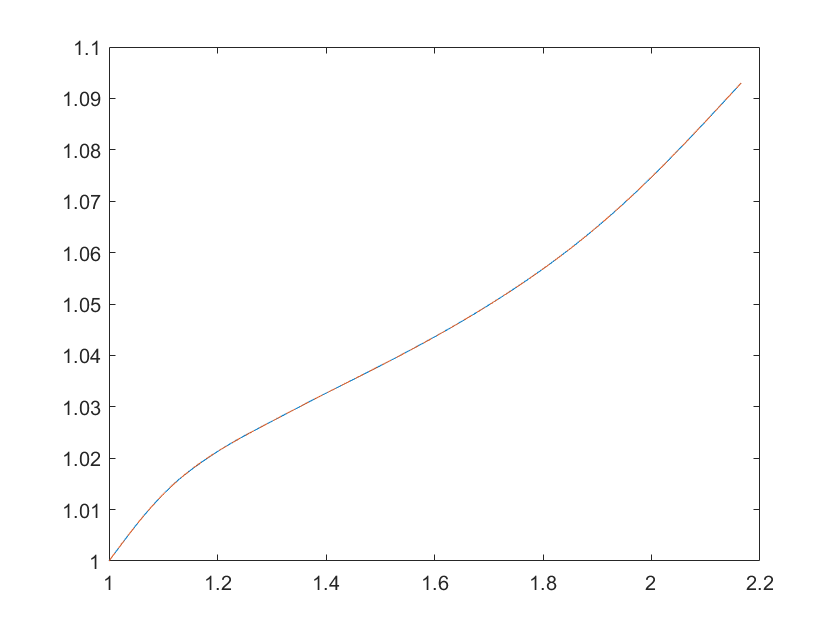

traj_pts_new = traj_pts;
traj_n_s = time_uniform_filter(traj,t_traj,traj_pts_new);
[PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj_n_s,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);

figure()
plot(traj_n_s(:,1),traj_n_s(:,2))
hold on
plot(traj(:,1),traj(:,2),'--')
hold off

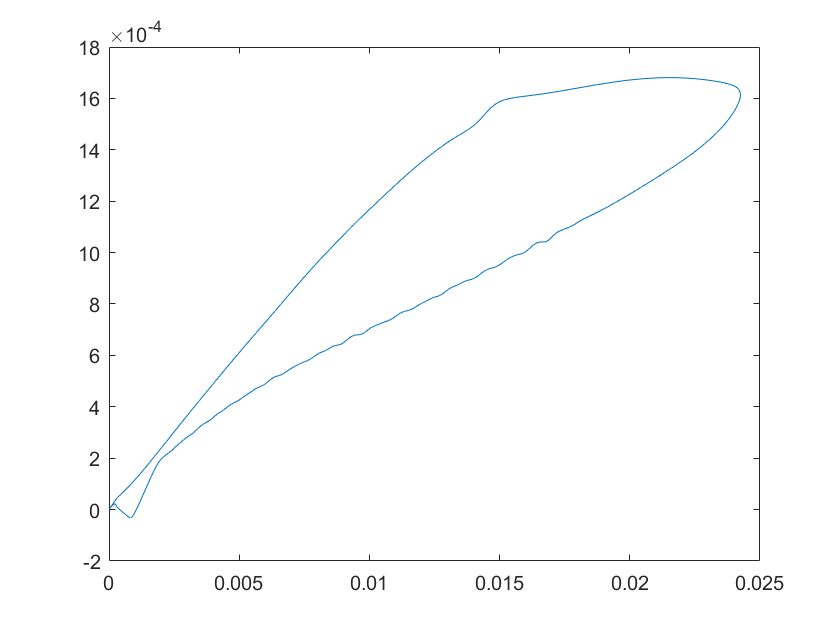

figure()
plot(PS_traj(:,3),PS_traj(:,4))  